# 3.1. Construcción del modelo 

## Preguntas Práctica 1:

    **1. Identificación de los componentes de la planta. Placa de desarrollo, Placa de expansión, Motor, Fuente de alimentación, etc. **

En estas prácticas trabajaremos con un montaje que consiste de los siguientres componentes:

- Motor EMG30 con reductora y encoder:

Un motor de corriente contínua que admite hasta 12 V cuyo movimiento se reduce en una proporción 30:1 por el conjunto de ruedas de la reductora; y un encoder que muestrea a través de pulsos el giro del mtor y nos va apermitir concer su posición (giro)

- Controladora X NUCLEO IHM15A1

Esta placa compuesta por la placa de desarrollo NUCLEO-F411RE y la placa de expansión X-NUCLEO-IHM04A1 contiene los principales componentes necesarios para el control de la señal que se administra al motor. Contiene el puente H (habrá dos de ellos) que es el circuito integrado que nos va a permitir variar el sentido de giro. Esta placa será la responsable de generar la señal PWM para controlar la velocidad del motor así como se encargará de recibir la señal de los encoders. El microprocesador será el que almacene y ejecute el código cargado desde el ordenador al que se conectará por micro-USB.

- Fuente de alimentación

Será la que alimentará al motor a través del puente H.

    **2. Comprobar que todo el Hardware está configurado de acuerdo a la descripción de estas notas.** 

Se trata de comprobar que la fuente de alimentación está configurada en 12 V y que las conexiones entre los componentes siguen las pautas del guión, así como la conexión de la placa al ordenador es correcta y se puede reconocer en este caso en el COM6. En Simulink tendremos que especificar el tiipo de placa NUCLEO-F411RE en Hardware Settings

 **   3. Montar el modelo de Simulink para el manejo del motor en lazo abierto. Configurarlo y comprobar que funciona correctamente, haciendo que el motor se mueva**

En la libreria de STMicroelectronic Nucleo Boards vamos a encontrar los bloques que vamos a necesitar para interactuar con la placa

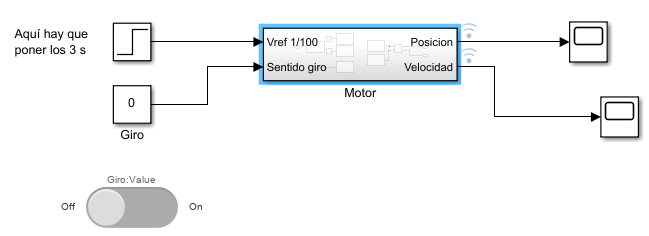

Bloque motor:

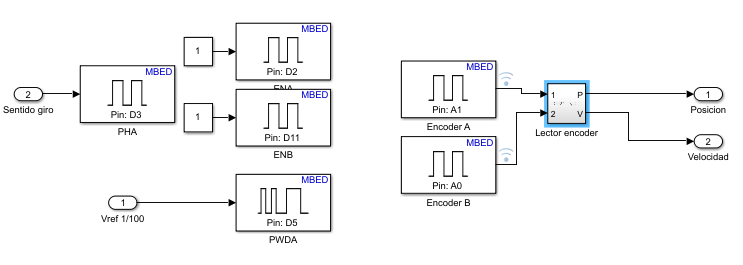

Lector encoder:

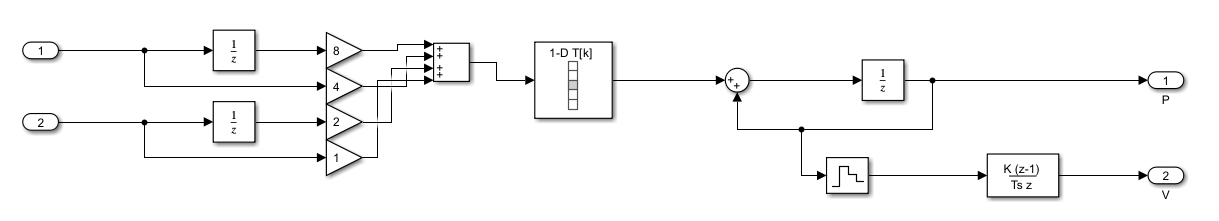

En la segunda foto entran en juego los bloques carácterísticos de la librería. Los bloques marcados como ENA y ENB conectados a los pines D2 y D11 son bloques que permiten cambiar el valor de los pines (Digital Write) habilitarán los puentes H A y B de la placa auxiiar conectados a esos pines. PHA en este caso en el pin D3 definirá el sentido de giro. El PWDA sera el que module la señal de entrada al motor, se le especificará una frecuencia de señal en este caso de 5000Hz y la entrada que recibe es el porcentaje de alimentación que dejará pasar al motor en forma de señal.

Los bloques de encoder A y B son digital read que recibirán la señal de los pines correspondientes los cuales son las señales del encoder. Necesitamos entonces llevar las señales de encoder a una lectura de velocidad y posició que podamos interpretar. Para consegirlo se emplea el Lector Encoder que es la tercera imagen. En este bloque se siguen los pasos del guión para transformar el recuento llevado a cabo por el encoder en una señal útil.

    **4. Recoger datos de velocidad y posición para diversos valores del voltaje de entrada. Observar también las señales de los encoders y discutir su validez**

**Para 5 voltios**

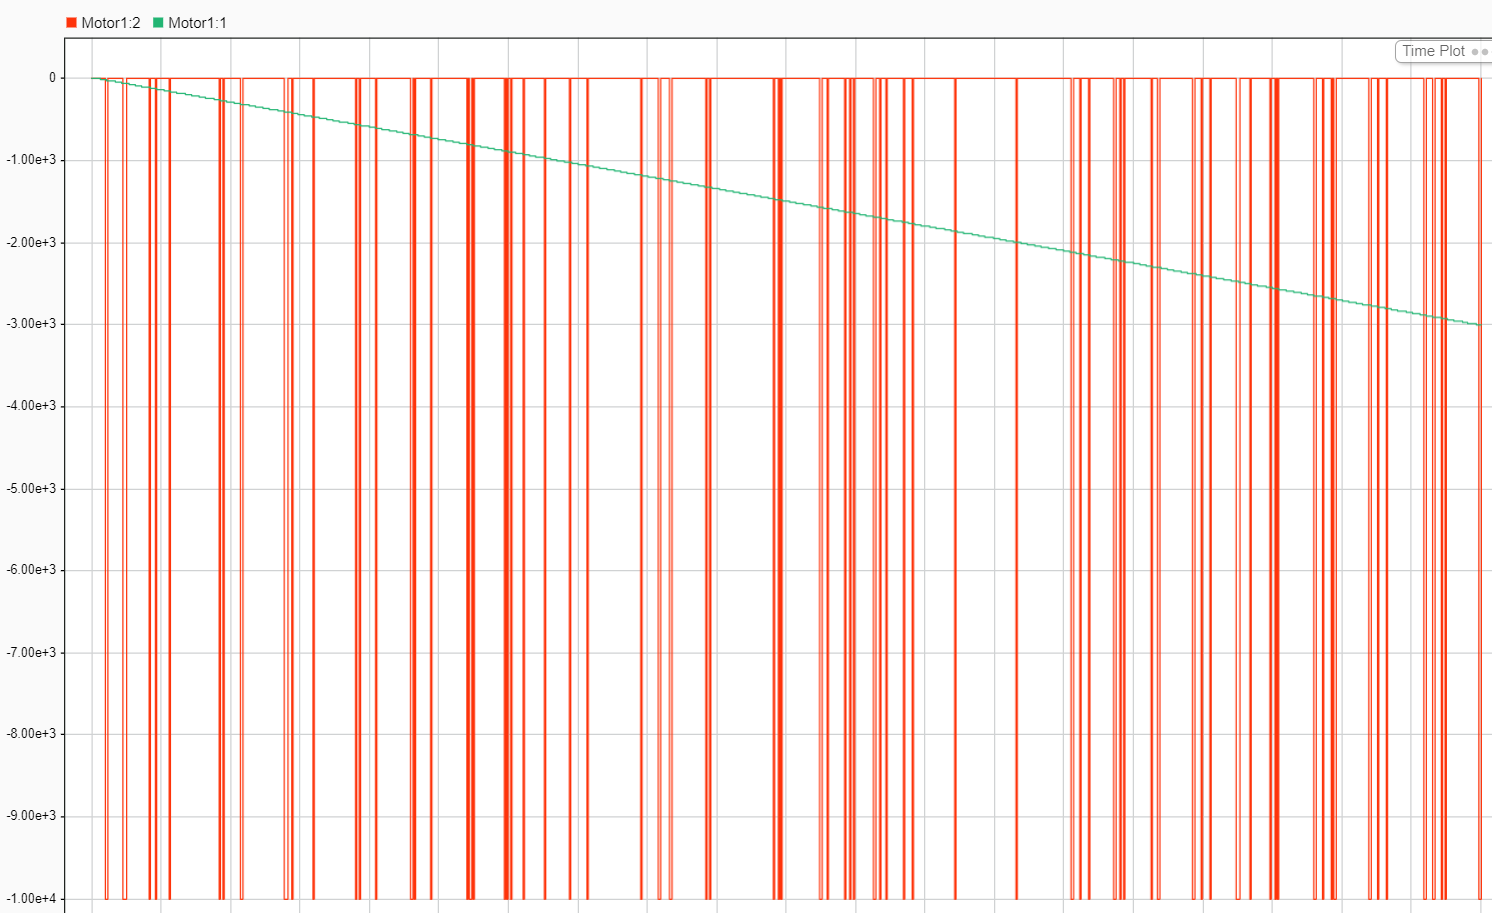

Con encoders:

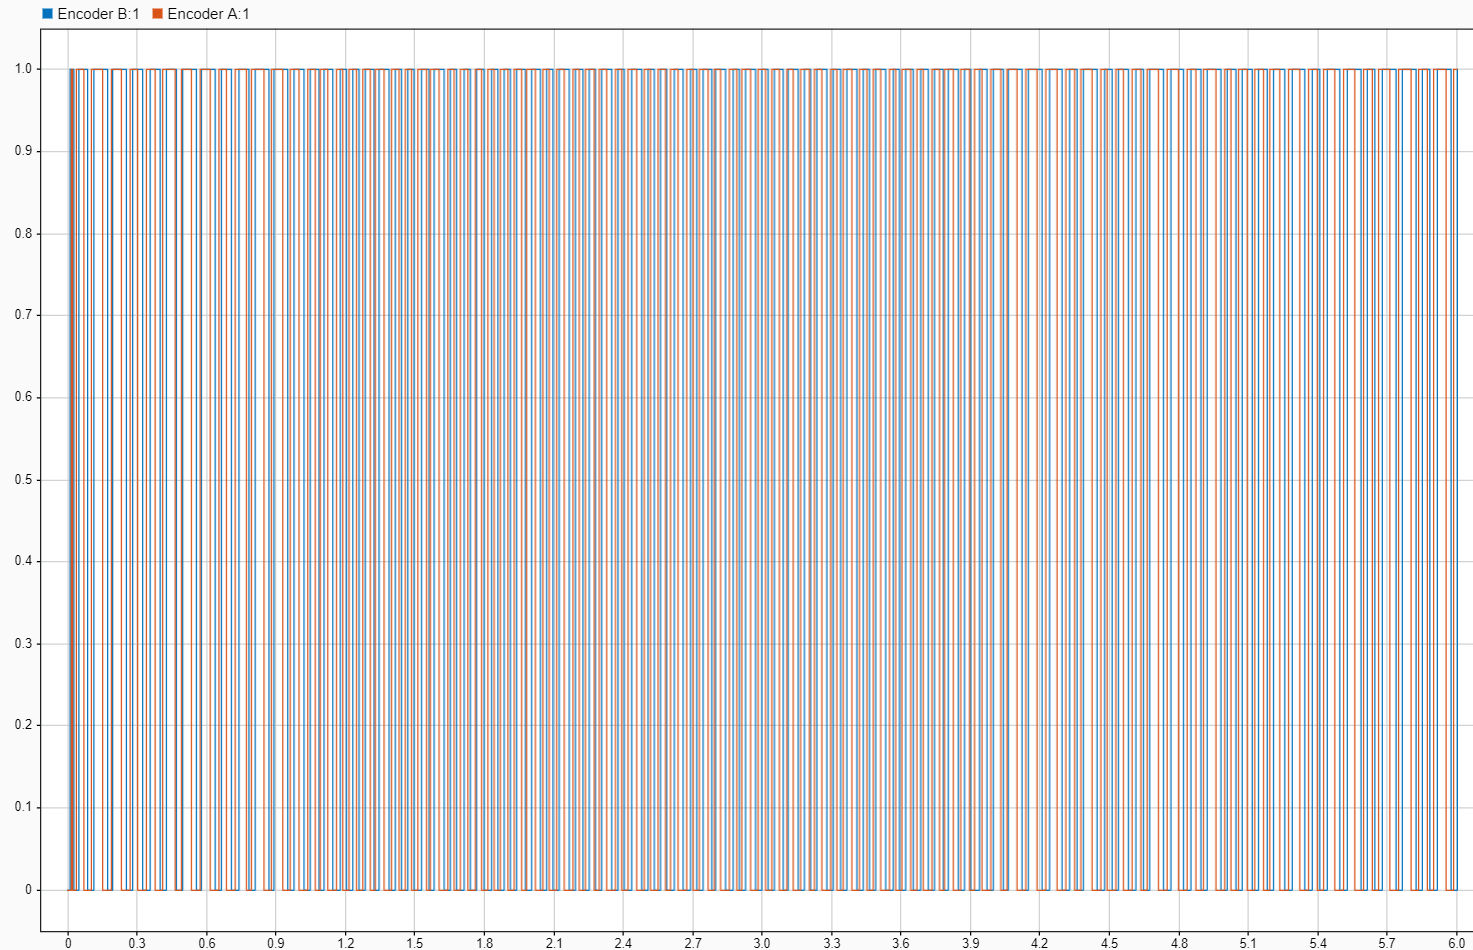

Para 12 voltios

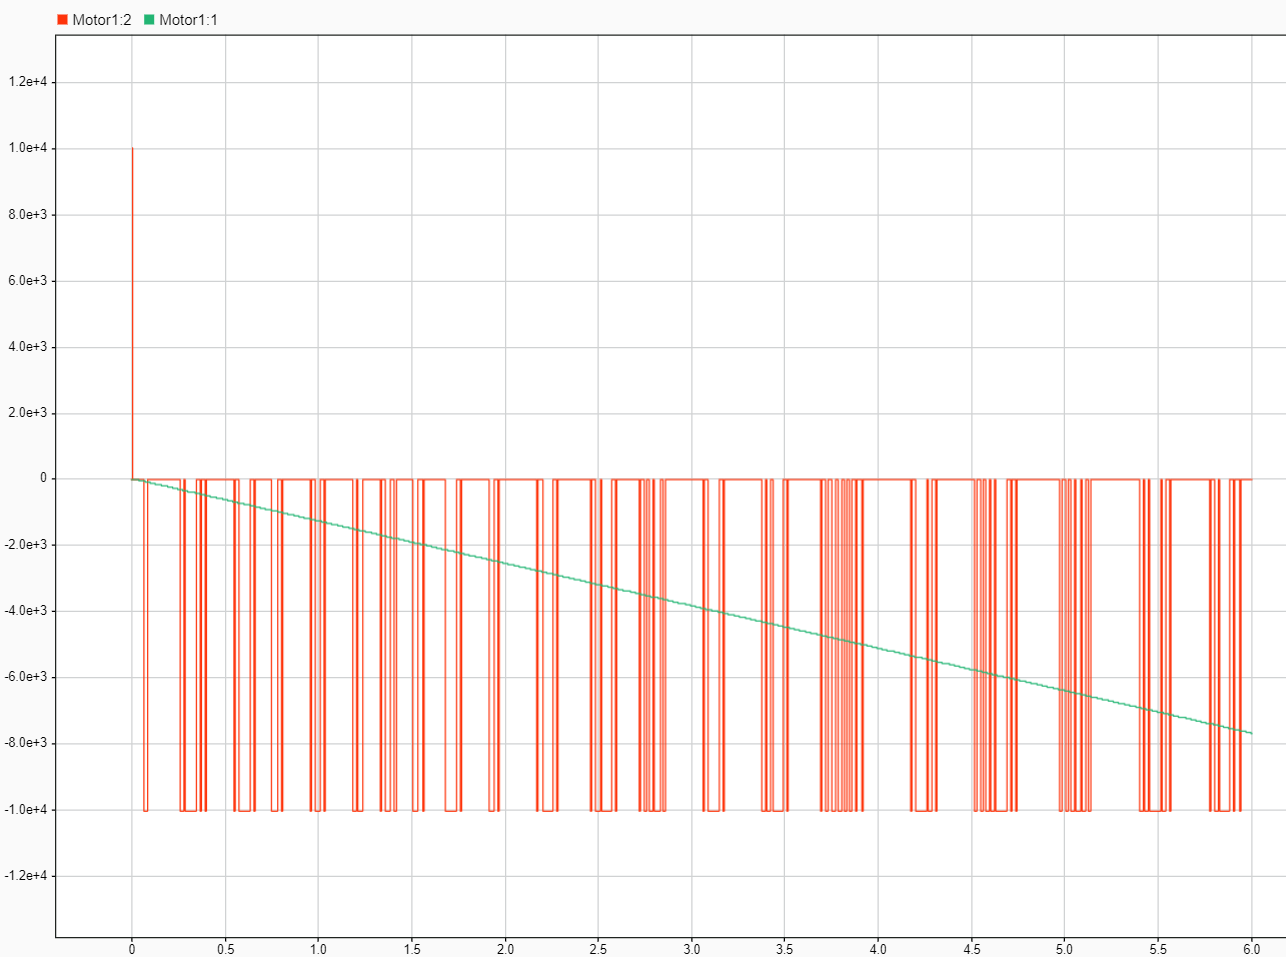

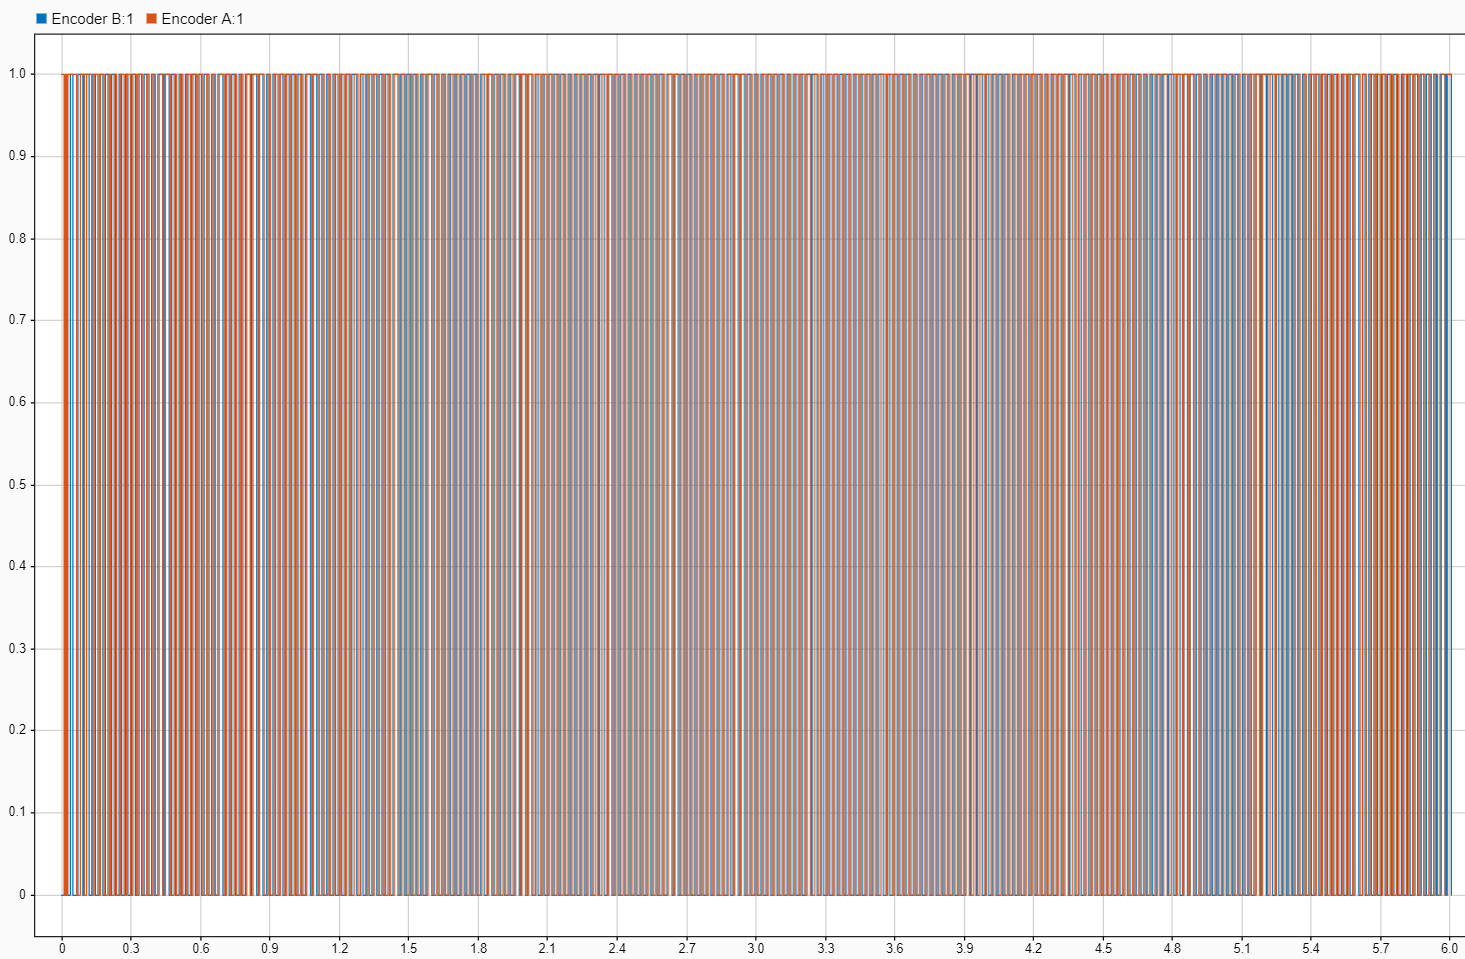

Con mucha mayor densidad de pulsos para el encoder

# 3.2. Modelo e identificación del motor

## Preguntas Práctica 2:

   ** 1. Obtener a partir de cálculo simbólico la expresión correspondiente a la posición angular de un motor de continua (ecuación 3.14). Obtenerla a partir del modelo en variables de estado y a partir de la función de transferencia. Calcular también la expresión correspondiente a la velocidad angular. **

Simbólico e(t)=V

syms omega(t)
syms theta(t)
syms mu a R R_0 J K_a e T_L p K_e V

ode=diff(theta,t,1)==omega

$$ode(t) = \frac{\partial }{\partial t}\theta \left(t\right)=\omega \left(t\right)$$

ode2=diff(omega,t,1)==-((1/J)*(mu+((a^2)/(R+R_0)))*omega)+((1/J)*((a*K_a)/(R+R_0))*V)-((1/J)*T_L)

$$ode2(t) = \frac{\partial }{\partial t}\omega \left(t\right)=\frac{K_{a}\,V\,a}{J\,\left(R+R_{0}\right)}-\frac{\omega \left(t\right)\,\left(\mu +\frac{a^{2}}{R+R_{0}}\right)}{J}-\frac{T_{L}}{J}$$


ode=diff(theta,t,1)==omega

$$ode(t) = \frac{\partial }{\partial t}\theta \left(t\right)=\omega \left(t\right)$$

ode2=diff(omega,t,1)==-p*omega+K_e*V

$$ode2(t) = \frac{\partial }{\partial t}\omega \left(t\right)=K_{e}\,V-p\,\omega \left(t\right)$$

Ahora resolvemos para theta

eqn=[ode,ode2];
[omega1,theta1]=dsolve(eqn);
simplify(theta1)

$$ans = -\frac{K_{e}\,V-C_{1}\,p^{2}+C_{2}\,p\,{\mathrm{e}}^{-p\,t}-K_{e}\,V\,p\,t}{p^{2}}$$

simplify(omega1)

$$ans = \frac{K_{e}\,V+C_{2}\,p\,{\mathrm{e}}^{-p\,t}}{p}$$

    Donde C1=0 y C2=$V\frac{K_e}{p^2}$

Que se puede ver si introducimos la condición inicial $\theta (0)=0$

**    2. Construir un modelo del motor de cc en Simulink. Se puede hacer a partir de las ecuaciones de estado o de funciones de transferencia, pero de modo que se pueda obtener tanto la posición como la velocidad angular. El modelo deberá obtener los parámetros ke y p del workspace de Matlab. Emplear el modelo de Simulink para el control del motor, construido en la práctica anterior, en lazo abierto para identificar el motor real. Es decir para obtener sus parámetros ke y p. Para ello: Obtener la respuesta del motor para distintos voltajes (por ejemplo incrementando el valor de la entrada de dos voltios en dos voltios desde 0 a 12V) y un tiempo de simulación en todos los casos de 3s. Calcular por regresión lineal la pendiente y el término independiente de la respuesta en estado estacionario. Estimar los valores de Ke y p para cada valor del voltaje de entrada ¿Qué se puede concluir? **

Los datos obtenidos para los diferentes voltajes y una diración de giro de 3 segundos se representan en la siguiente gráfica.

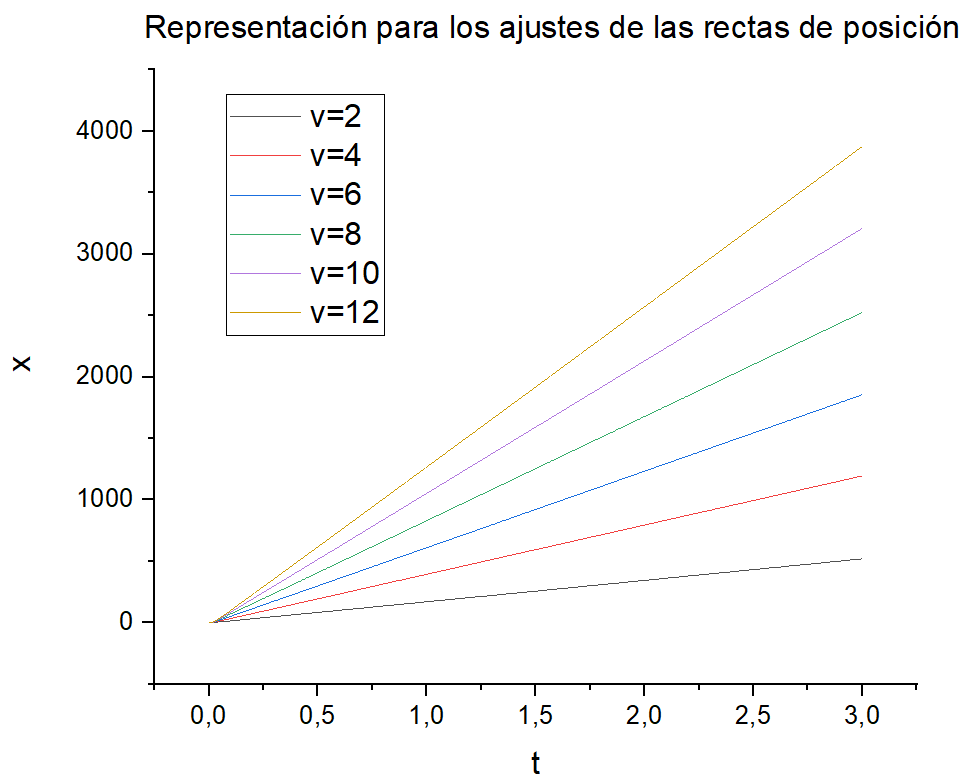

Los valores obtenidos tras el ajuste para voltajes entre 2 y 12 son:

- 12        $K_e=4497,14
$    $P=41,447$

- 10        $K_e=5316,29
$    $P=49,365$

- 8          $K_e=6407,48
$    $P=60,56
$

- 6          $K_e=6703,79
$    $P=64,68$

- 4          $K_e=8639,23
$    $P=86,38$

- 2          $K_e=5874,28
$    $P=67,529$

Dando entonces unos valores medios de:

- Media:  $K_e=6239,7$    $P=61,66
$

Que son los que emplearemos de ahora en adelante para realizar la práctica. Podemos ver que son parámetros que tienen una gran variabilidad conforme al voltaje alcanzando ambos un máximo en 4V lo cual puede ser debido a los cambios en la eficiencia del motor dependiendo del voltaje pudiendo ser esta una relación no lineal. Pero para la práctica con un sistema de control que incluye realimentación el error que puede generar el modelo para una extrapolación grande será absorbido por es sistema.

El modelo de simulink con las constantes quedará:

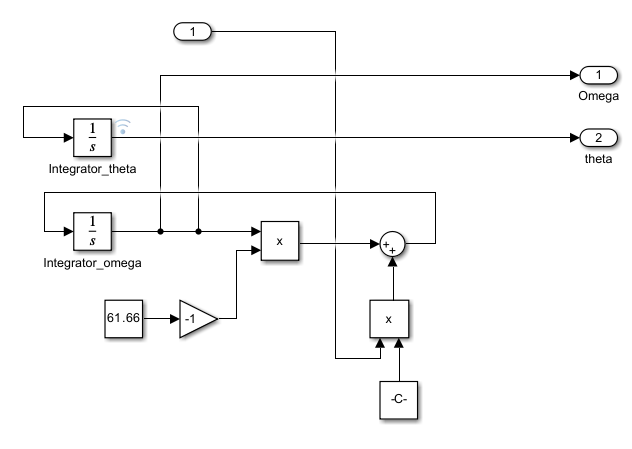

**  3. Introducir los valores obtenidos de Ke y p en el modelo de motor desarrollado en Simulink (obtener unos valores promedio razonables) Comparar los resultados del modelo con el sistema real. **

No se pudieron recoger los datos pero serán empleados con ejemplos en lasa siguientes cuestiones.

# 4.1. Un modelo completo del motor 

## Preguntas Práctica 3:

    **1. Construir un modelo completo del motor, a partir del modelo de motor ideal construido en la Práctica 2. Añadir el mismo bloque de lectura de encoders construido para leer los encoders del motor real. **

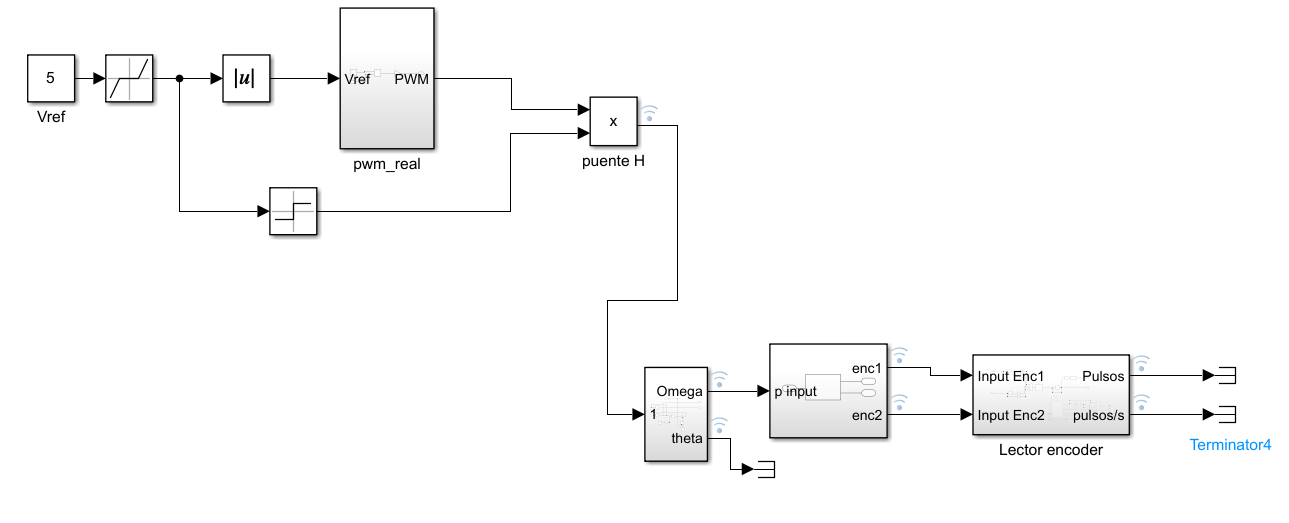

   **2. Simular el comportamiento del modelo para distintos valores del voltaje de entrada Vref. Comparar la salida directa (posición y velocidad) del motor con la que se obtiene a partir de la lectura de los encoders Comparar los valores de las lecturas de velocidad y posición obtenidas a través de los encoders para el motor real y para el modelo.**

V=5

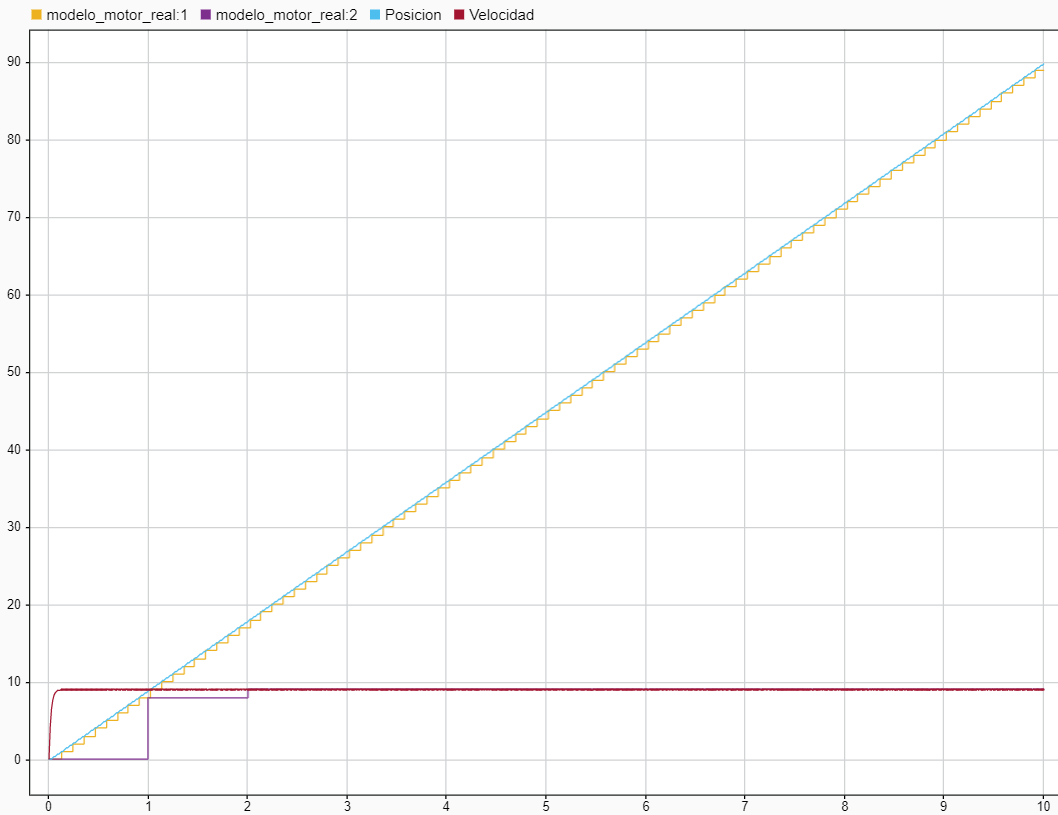

V=10 (ampliado a los tres primeros segundos):

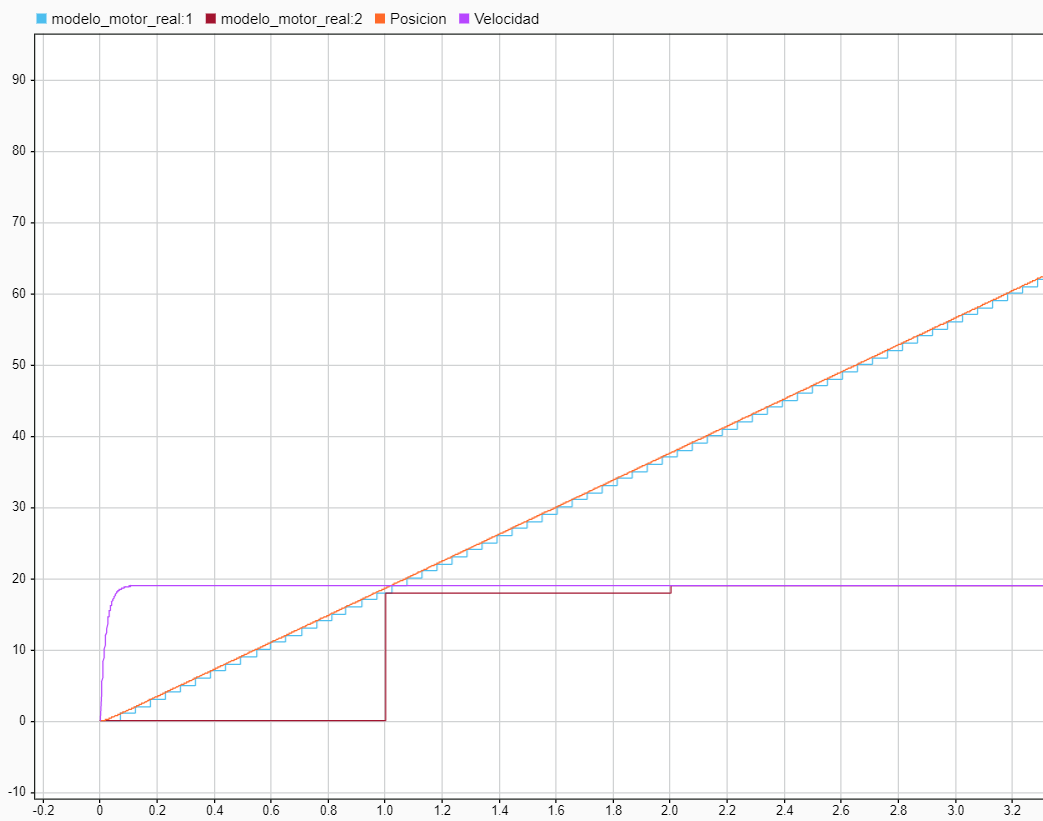

Vemos que la velocidad aumenta al doble entre uno y otro voltaje. Que las señales se siguen pero que la señal de velocidad del modelo no tiene el comportamiento que se espera.

# 4.2. Diseño de un controlador por realimentación de estados estimados

## 4.2.1 Controlador para el motor ideal 

Construimos para el modelo de motor ideal una realimentación de la forma:

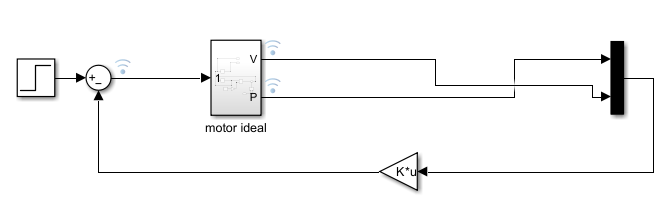

Al cual alimentaremos una ganancia con los autovalores de una matriz A con p'=p/2

Si hacemos la prueba con P=50 y K_e=100 para comparar con los ejemplos del guión obtenemos:

A=[0,1;0,-50];
B=[0;100];
[V,D]=eig(A)

V =     1.0000   -0.0200
         0    0.9998


D =      0     0
     0   -50


A_tilde=[0,1;0,-25];
[V_tilde,D_tilde]=eig(A_tilde)

V_tilde =     1.0000   -0.0400
         0    0.9992


D_tilde =      0     0
     0   -25


gan=acker(A,B,[-25,-25])

gan =     6.2500         0


Dando como resultado:

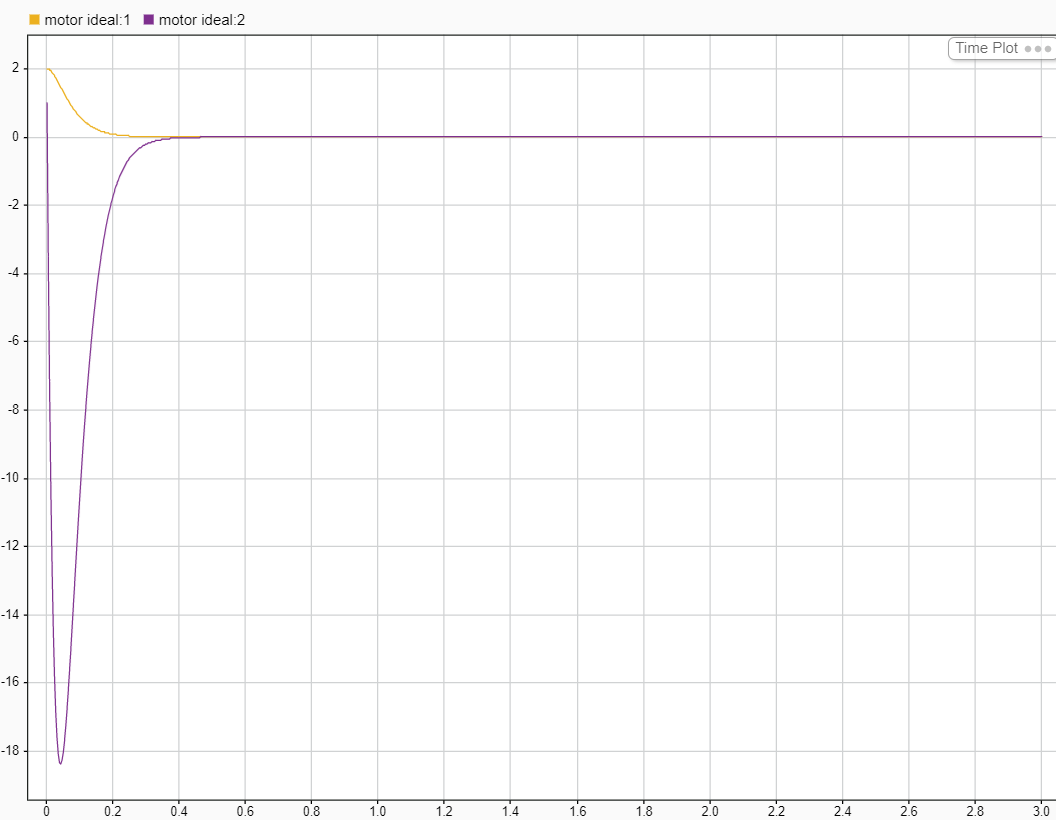

Y la señal de entrada:

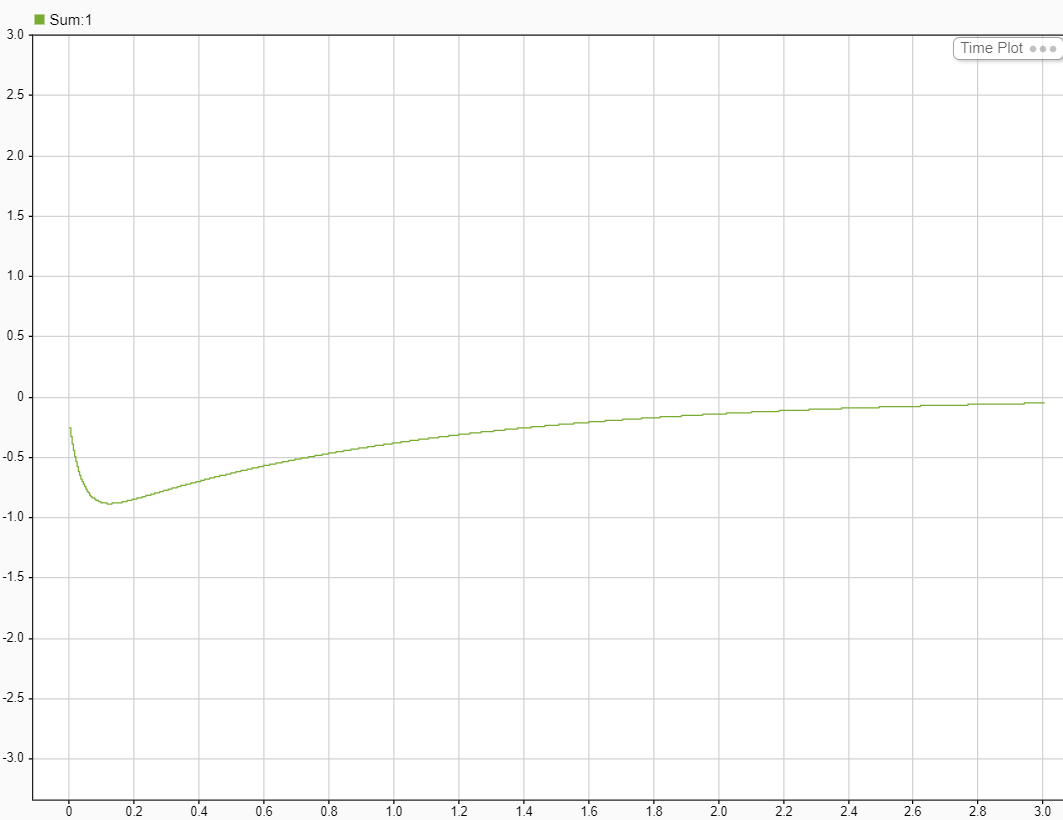

**Ahora vamos a volver a nuestros valores de P=61,66 y k_e=6239.7**

**Antes de entregarlo y comentandolo con compañeros me dí cuenta que muchos usaban los del guión pero yo empecé a usar los característicos del motor en esta parte**

A_tilde=[0,1;0,-61.66*1.2];
[V_tilde,D_tilde]=eig(A_tilde)

V_tilde =     1.0000   -0.0135
         0    0.9999


D_tilde =          0         0
         0  -73.9920


P=[-61.66*0.5;-61.66*0.5]

P =   -30.8300
  -30.8300


gan=acker(A,B,P)

gan =     9.5049    0.1166


Y empezamos con el estimador:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.2;-61.66*1.2];
L=acker(A,B,P)';

Podemos construir el modelo del estimador y comprobar las señales:

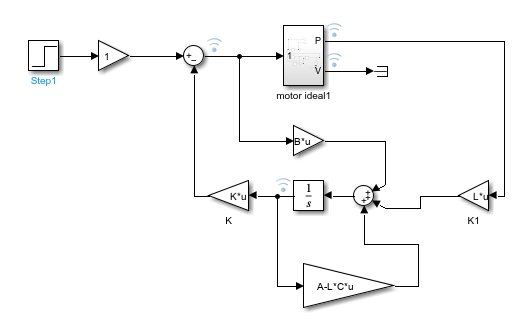

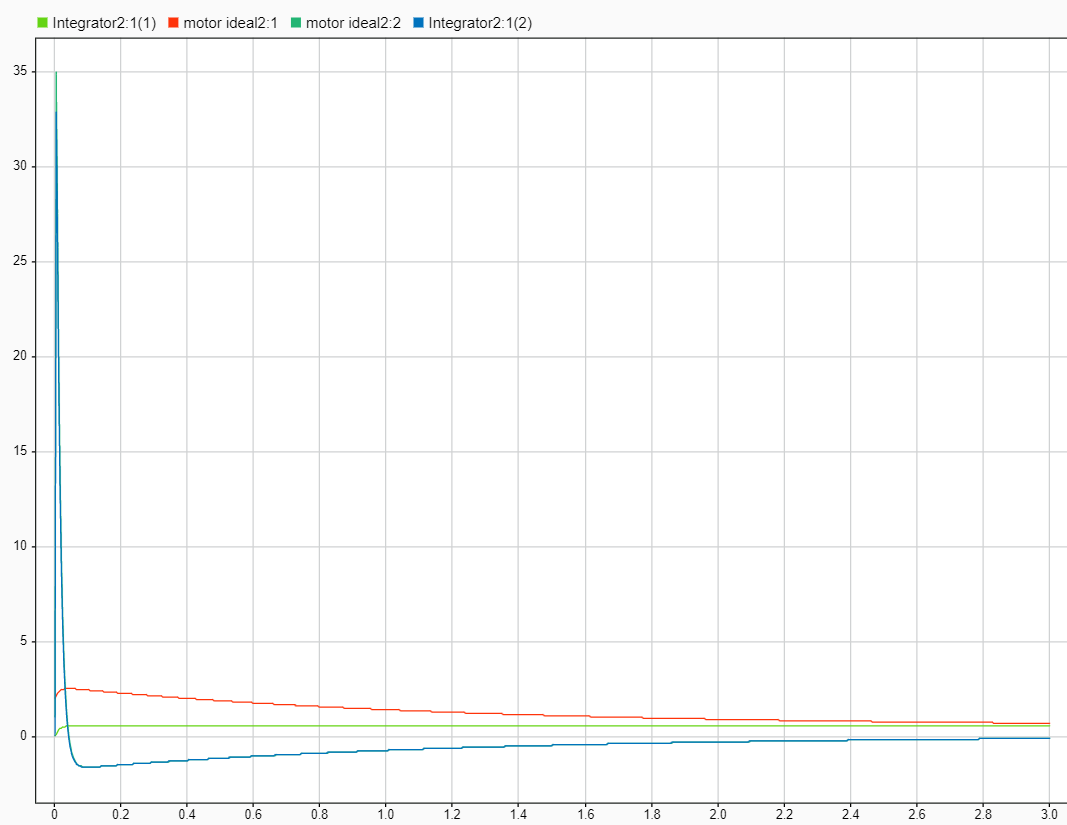

Donde el estimador de velocidad y la velocidad del motor están prácticamente una sobre la otra y se alcanza un equilibrio pero no sobre nuestro valor de entrada de la función escalón.

Ahora vamos a incorporar la acción integral:

P=[-61.66*0.5;-61.66*0.5]

P =   -30.8300
  -30.8300


gan=acker(A,B,P)

gan =     0.1523         0


A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.2;-61.66*1.2];
L=acker(A,B,P)'

L =     0.8774
    0.0138



c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp = 1.0e+03 *

         0
    6.2397
         0


P=[-61.66*0.5;-61.66*0.5;-61.66*1.5];
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 14.0889

K=[Kamp(1),Kamp(2)]

K =     1.0663    0.0148


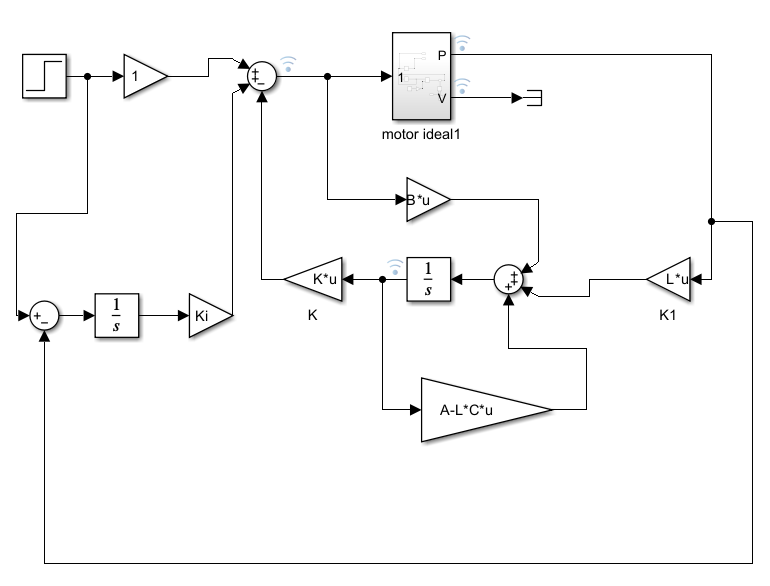

En los resultados vemos que se alcanza una saturación muy grande:

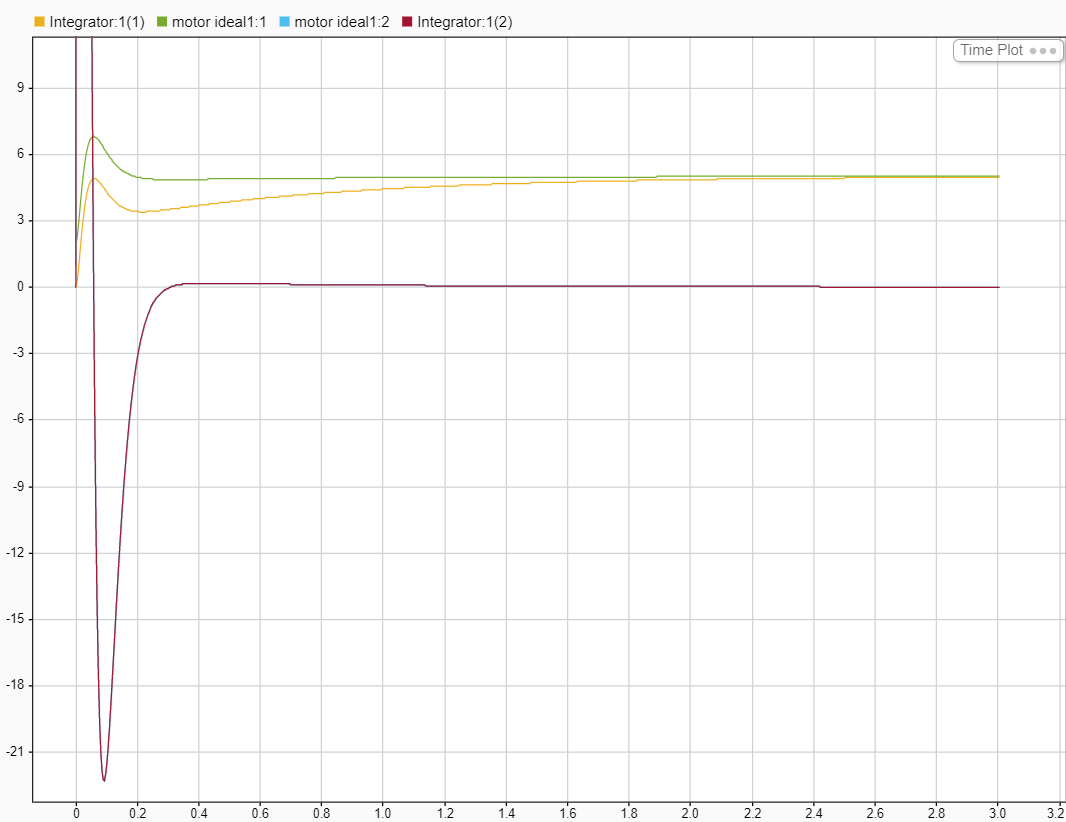

Haciendo zoom a nuestra región de interés distinguimos con la línea verde la posición estimada, con la naranja la posición del motor y vemos su convergencia.

Por otro lado estan las velocidades estimada y del motor que caen a 0 con la estabilización de la posición.

La convergencia es muy lenta y el estimador de velocidades muy rápido, por qué?

## Preguntas Práctica 4:

- **Hecho arriba**

- **Comprobar el efecto de la posición de los polos del sistema y el estimador sobre la velocidad de respuesta del sistema y el valor de la señal de control u. (incrementarlos o disminuirlos en potencias de 10) **

Vamos entonces a aumentar un factor 10:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5]*10;
L=acker(A,B,P)';

c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp = 1.0e+03 *

         0
    6.2397
         0


P=[-61.66*0.5;-61.66*0.5;-61.66*1.5]*10;
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 1.4089e+04

K=[Kamp(1),Kamp(2)]

K =   106.6305    0.2372


Vemos que conseguimos una respuesta de estabilización muy rápida:

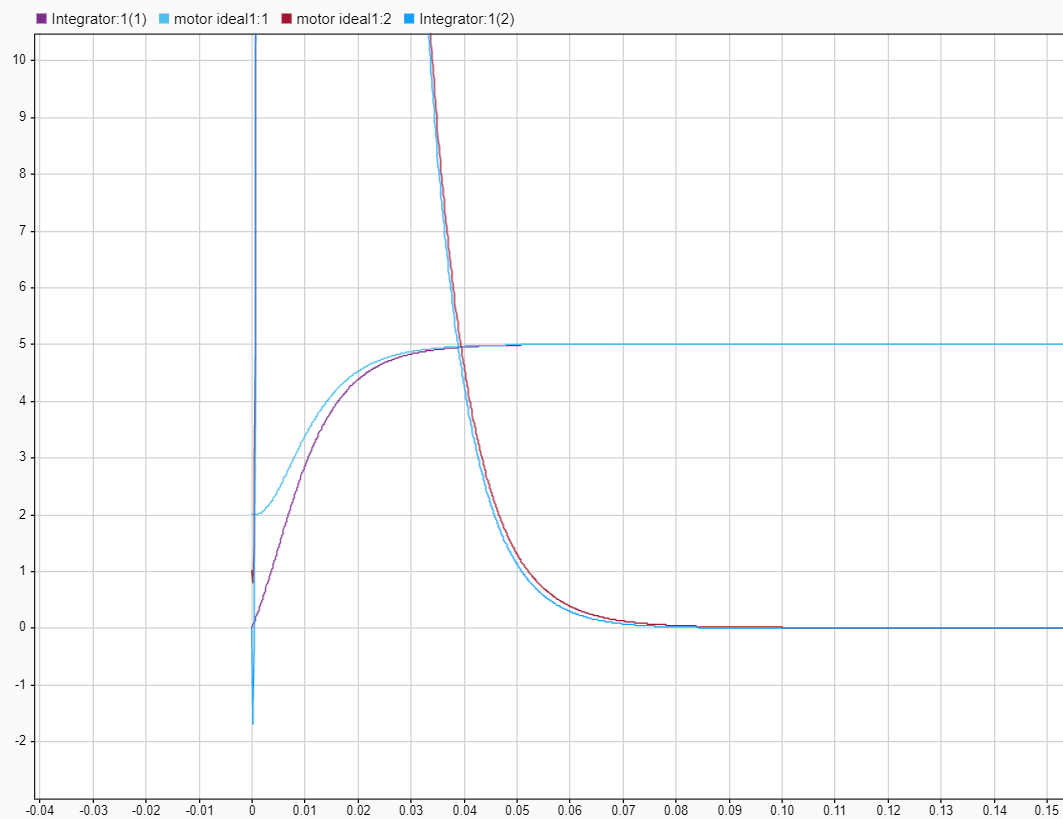

El valor de la entrada:

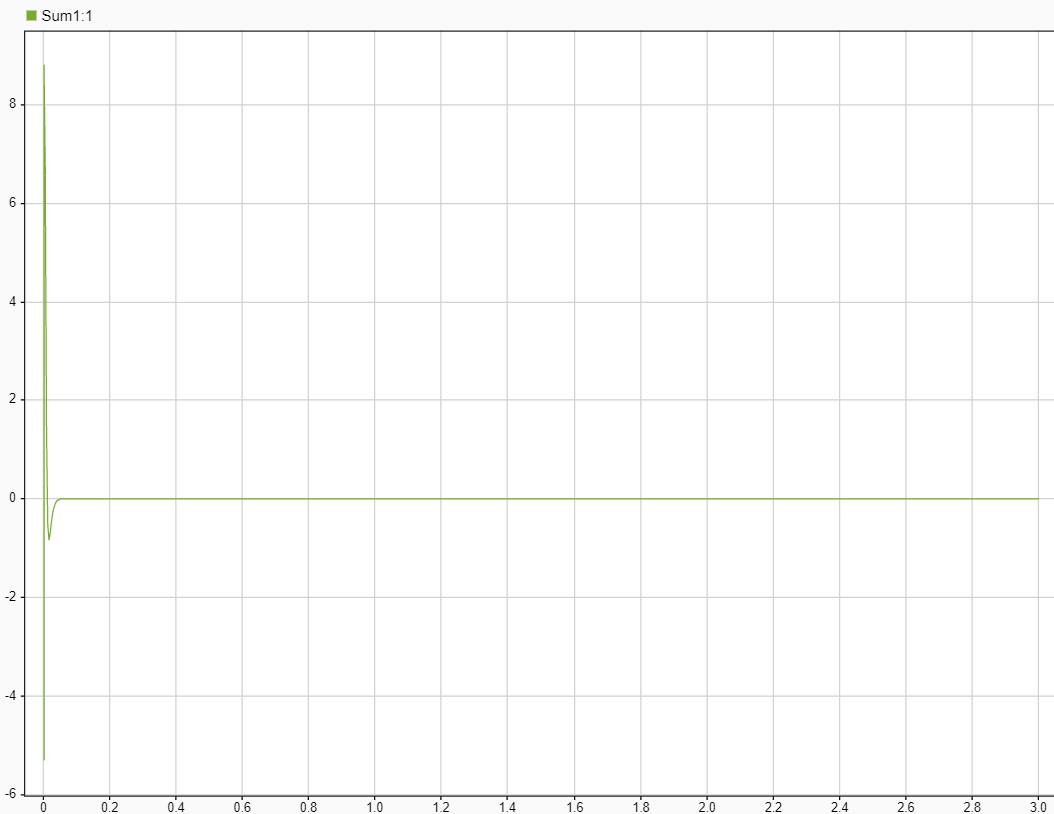

Vemos que satura el voltaje.

Vamos entonces a disminuir un factor 10:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5]./10;
L=acker(A,B,P)';

c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp = 1.0e+03 *

         0
    6.2397
         0


P=[-61.66*0.5;-61.66*0.5;-61.66*10*1.5]./10;
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 0.1409

K=[Kamp(1),Kamp(2)]

K =     0.0929    0.0059


El polo de la acción integral lo hemos dejado en su sitio.

Y ahora los autovalores del sistema pueden no estar lo suficientemente a la izquierda loq ue provoca:

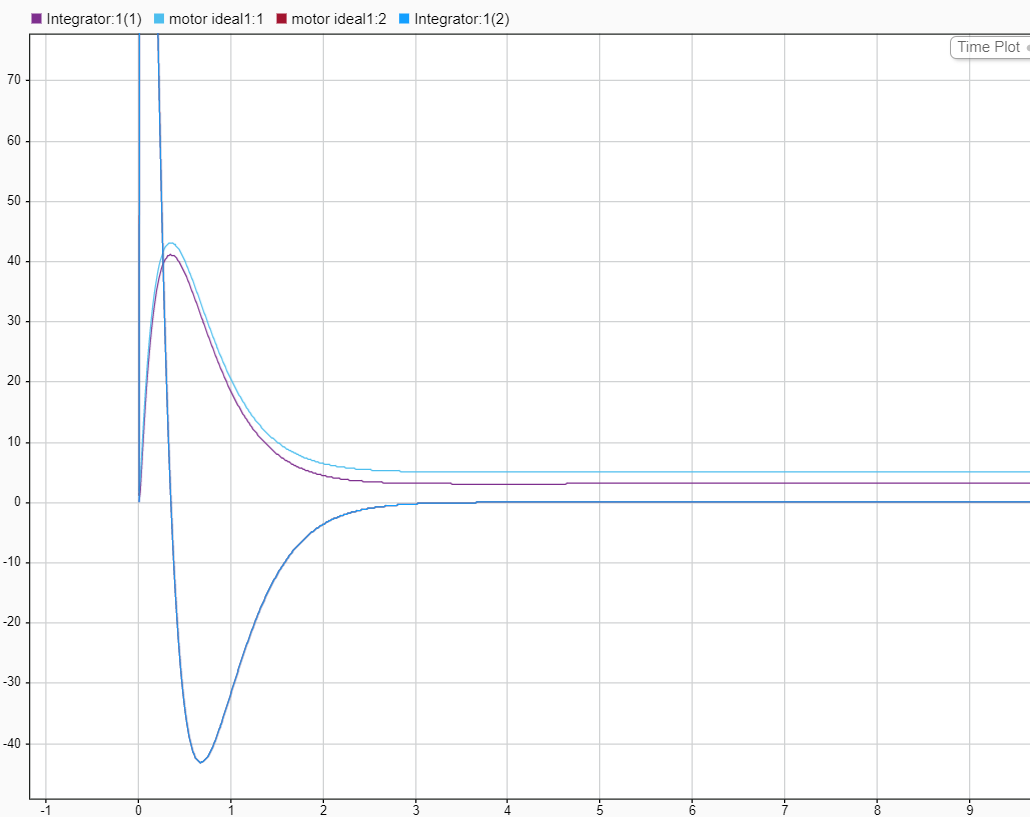

El valor de la entrada es el siguiente:

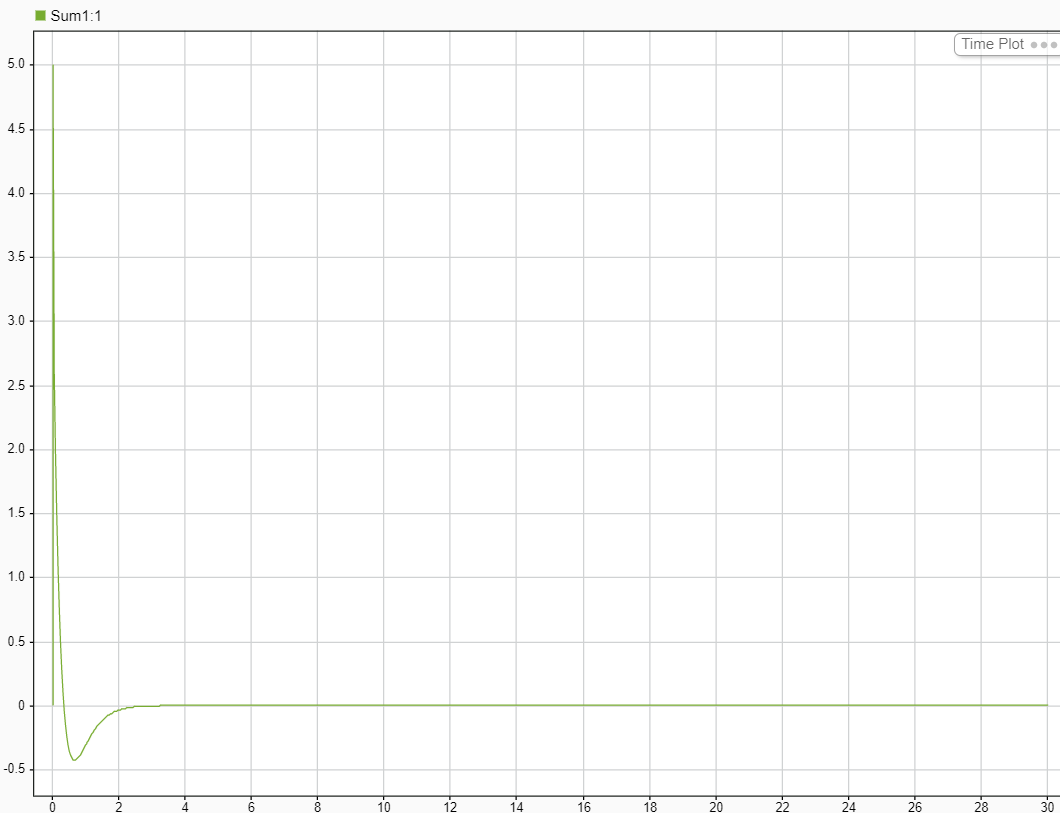

    **        3. Comprobar el efecto de la ganancia de la alimentación directa F.**

Volviendo a los valores normales de los polos:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';

c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp = 1.0e+03 *

         0
    6.2397
         0


P=[-61.66*0.5;-61.66*0.5;-61.66*1.5];
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 14.0889

K=[Kamp(1),Kamp(2)]

K =     1.0663    0.0148


        F=2:

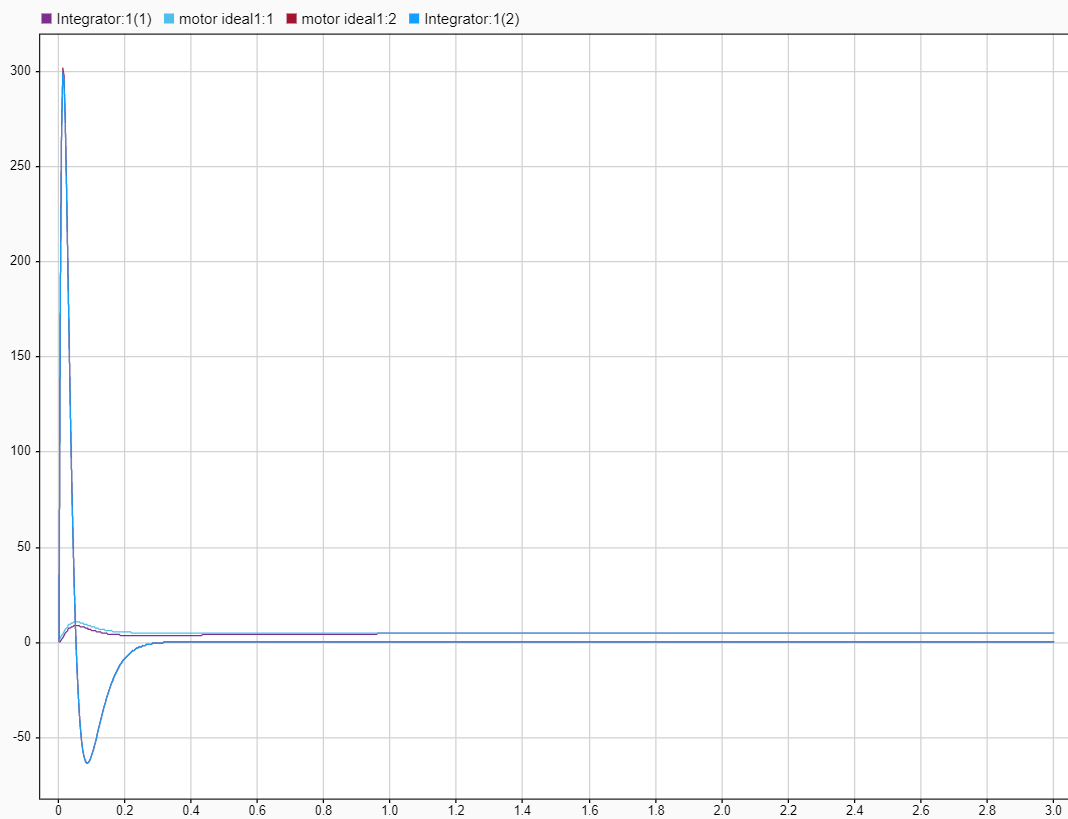

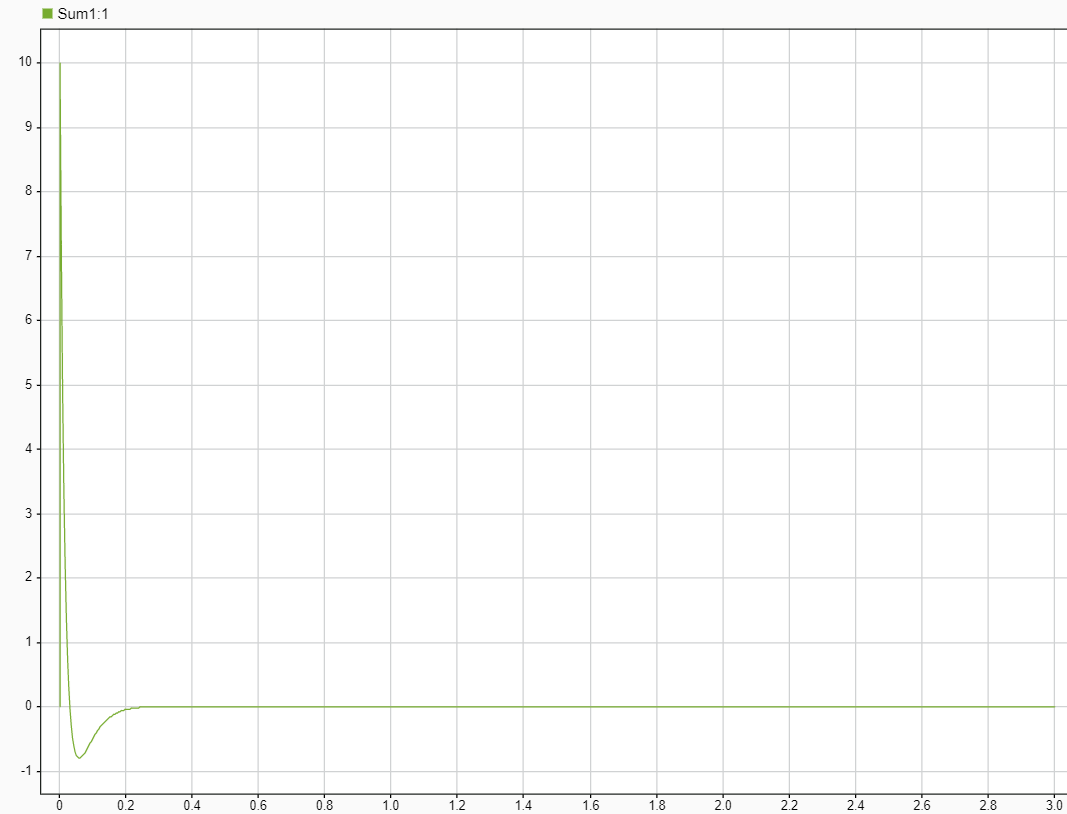      

      F=10:

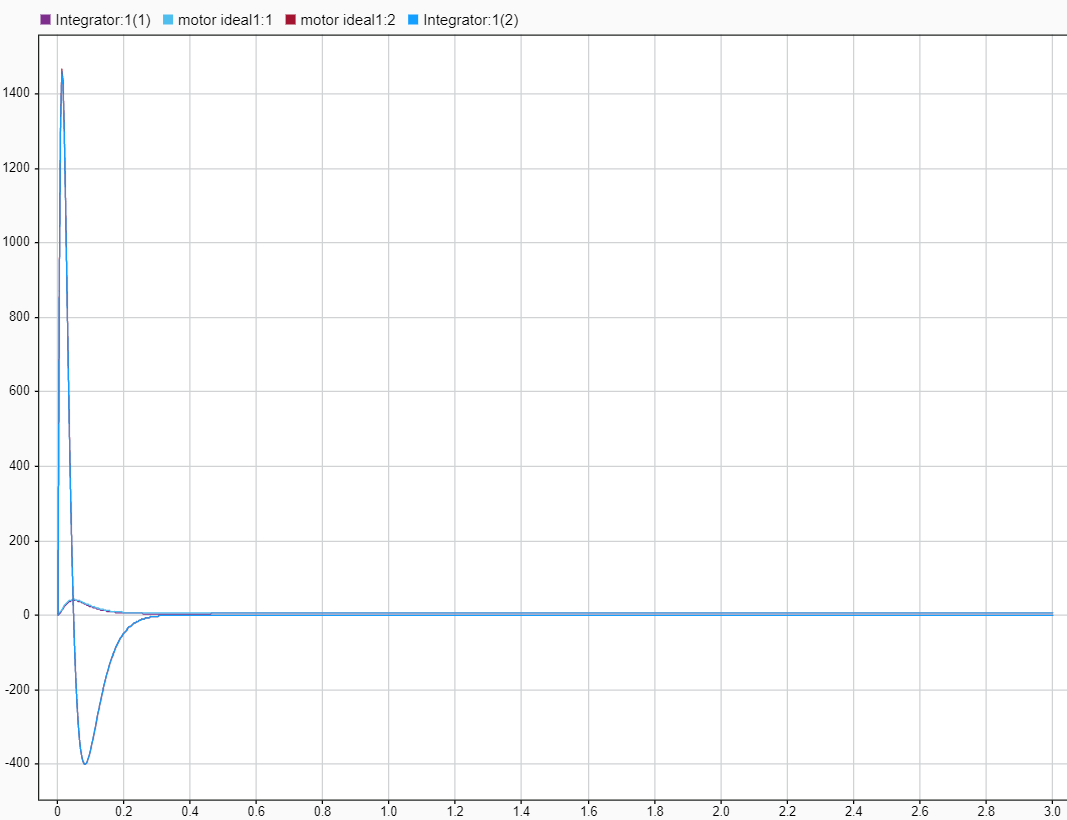

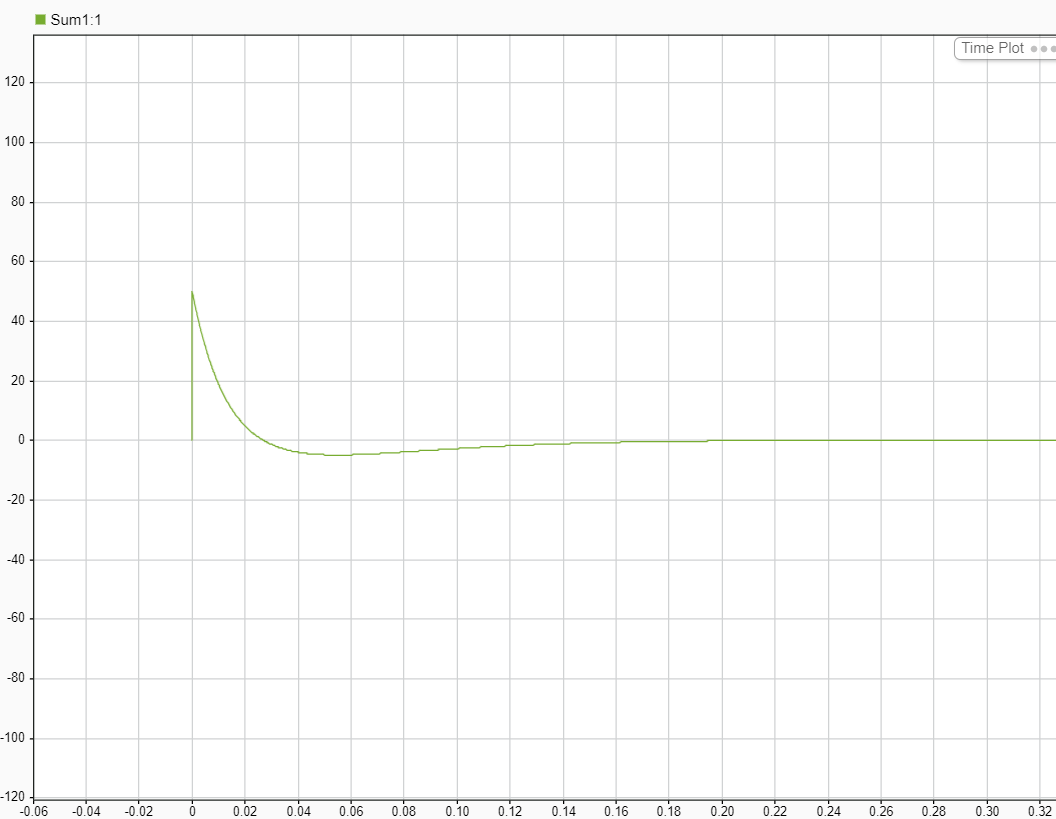

F nos va a permitir controlar la saturación de la señal para mantenerla en un rango de entrada donde pueda actuar nuestro motor.

          **  4. El error de posición inicial sobre u:**

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7]*10;
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';

c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp =            0
       62397
           0


P=[-61.66*0.5;-61.66*0.5;-61.66*1.5];
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 1.4089

K=[Kamp(1),Kamp(2)]

K =     0.1066    0.0015


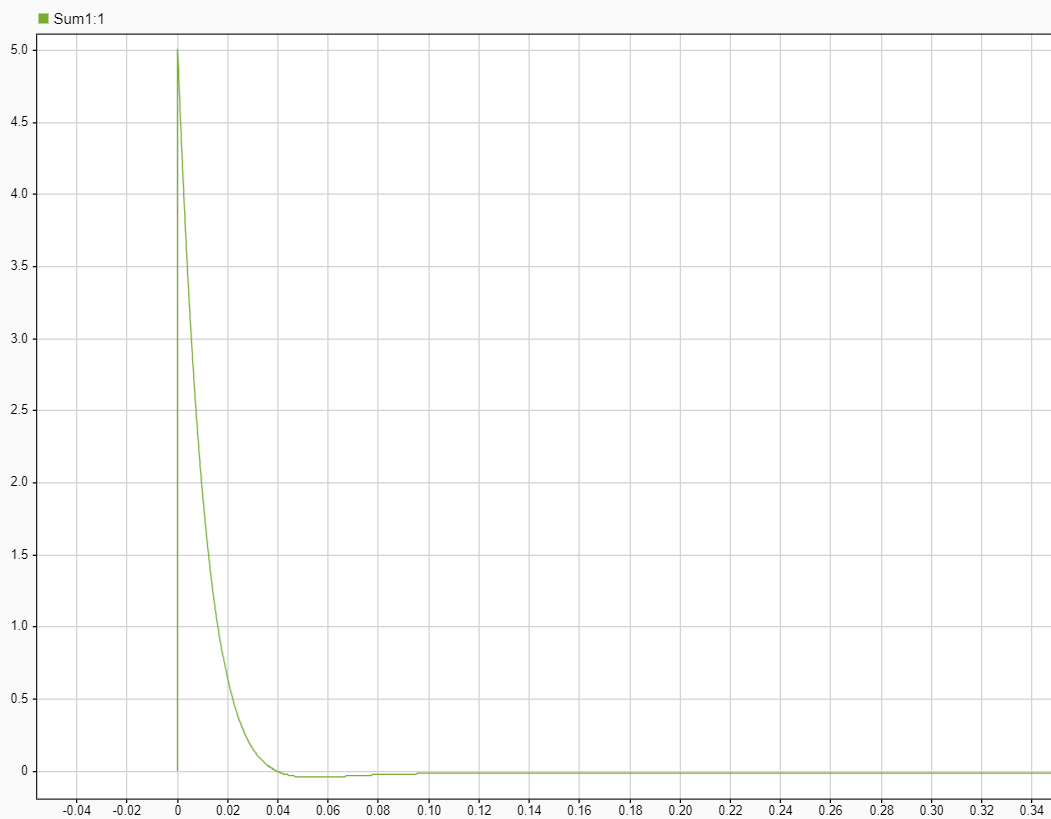

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7]/2;
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';

c0=1;
Aamp=[A,[0;0];c0,0,0]

Aamp =          0    1.0000         0
         0  -61.6600         0
    1.0000         0         0


Bamp=[B;0]

Bamp = 1.0e+03 *

         0
    3.1199
         0


P=[-61.66*0.5;-61.66*0.5;-61.66*1.5];
Kamp=acker(Aamp,Bamp,P)';
Ki=[Kamp(3)]

Ki = 28.1779

K=[Kamp(1),Kamp(2)]

K =     2.1326    0.0296


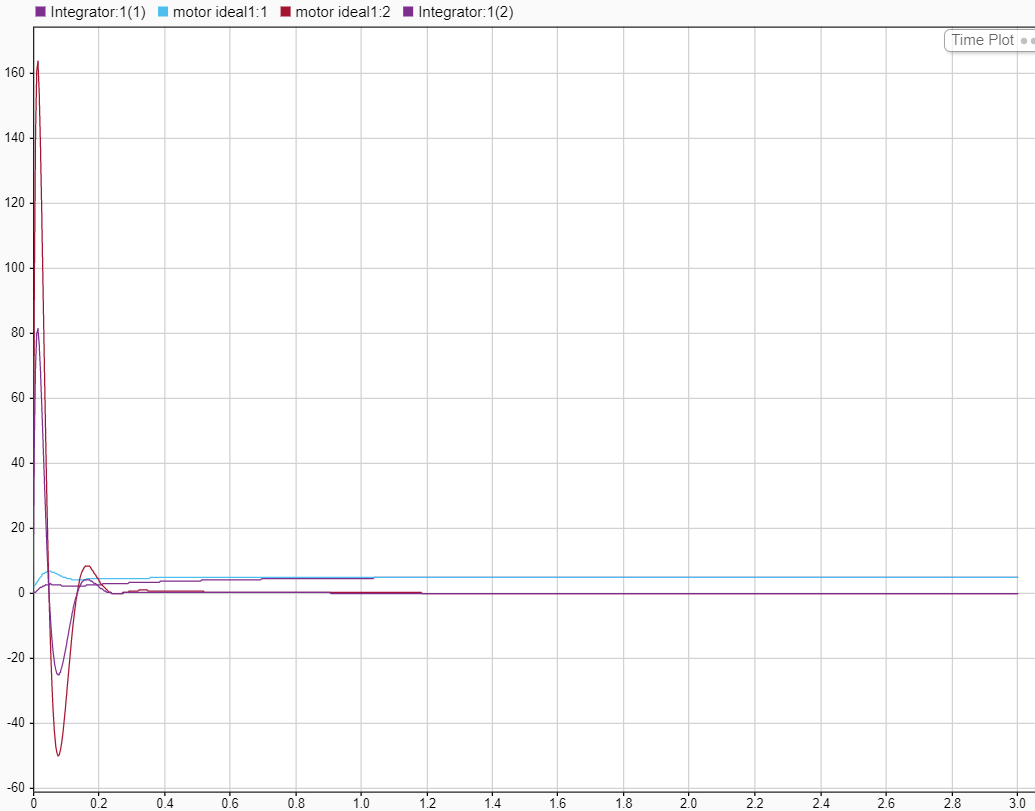

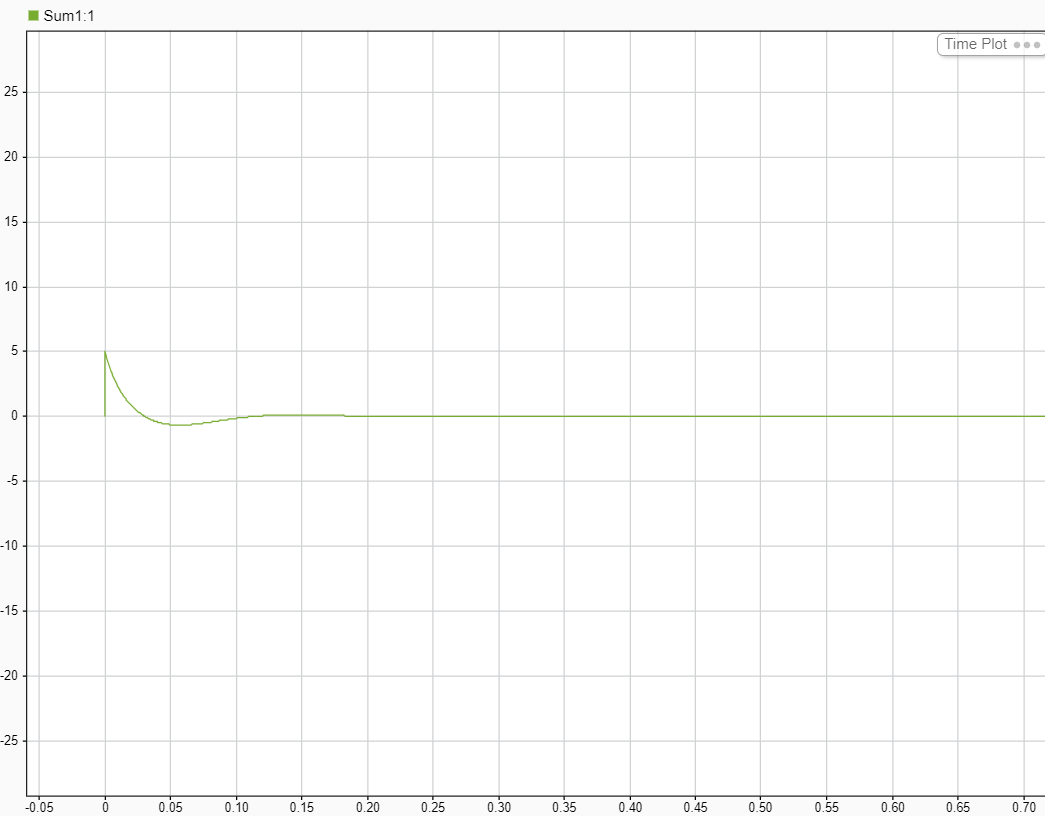

Vemos que se reduce la saturación 

## **4.2.2. **Discretización del controlador para control del motor real 

Prácticas 5 y 6:

El modelo de simulink discretizado será:

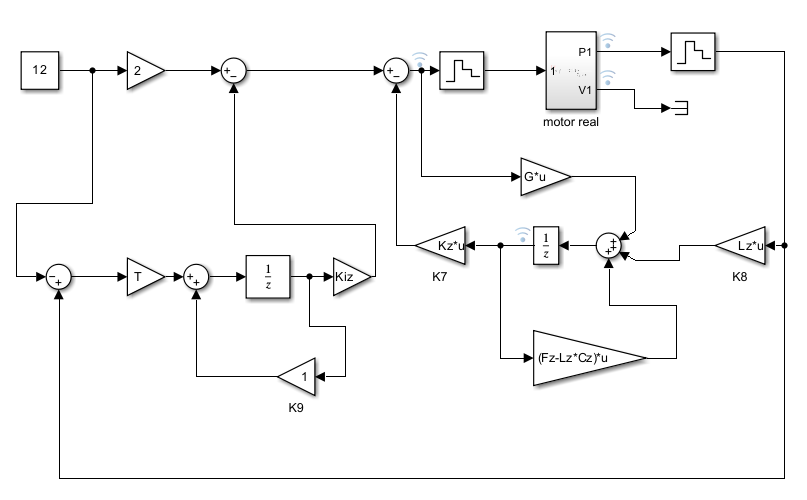

**F, G, C, D**

T=0.0001    %periodo de muestreo

T = 1.0000e-04

sys=ss(A,B,C,D)

sys =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -61.66
 
  B = 
         u1
   x1     0
   x2  3120
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties

sysd=c2d(sys,T)

sysd =
 
  A = 
              x1         x2
   x1          1  9.969e-05
   x2          0     0.9939
 
  B = 
              u1
   x1  1.557e-05
   x2      0.311
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.0001 seconds
Discrete-time state-space model.


Fz=[1,0.00009969;0,0.9939]

Fz =     1.0000    0.0001
         0    0.9939


Gz=[0.00001557;0.311]

Gz =     0.0000
    0.3110


P=[-61.66*1.2;-61.66*1.2]; %polos de L
Pexp=exp(P*T)

Pexp =     0.9926
    0.9926


Lz=acker(Fz,Gz,Pexp)'

Lz =     1.7475
    0.0277


P=[-61.66*0.5;-61.66*0.5]; %polos de K y ki
Pexp=exp(P*T)

Pexp =     0.9969
    0.9969


K=acker(Fz,Gz,Pexp)

K =     0.3047    0.0002


Las ampliadas:

Famp=[Fz,[0;0];T*C,1]

Famp =     1.0000    0.0001         0
         0    0.9939         0
    0.0001         0    1.0000


Gamp=[Gz;0]

Gamp =     0.0000
    0.3110
         0


Cz=C

Cz =      1     0


Dz=D

Dz = 0

P=[-61.66*0.5;-61.66*0.5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T)

Pexp =     0.9969
    0.9969
    0.9908


Kamp=acker(Famp,Gamp,Pexp)

Kamp =     2.1259    0.0297   28.0515


Kiz=[Kamp(3)]

Kiz = 28.0515

Kz=[Kamp(1),Kamp(2)]

Kz =     2.1259    0.0297


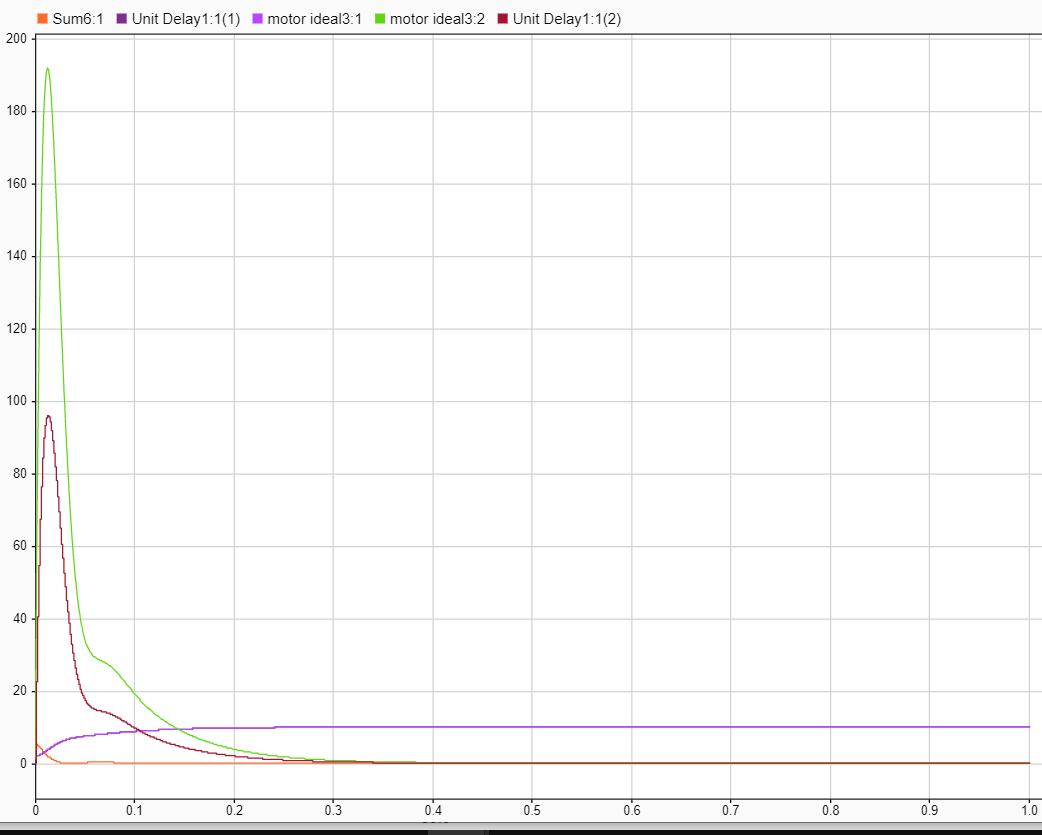

Haciendo zoom en la señal de seguimiento de la posición:

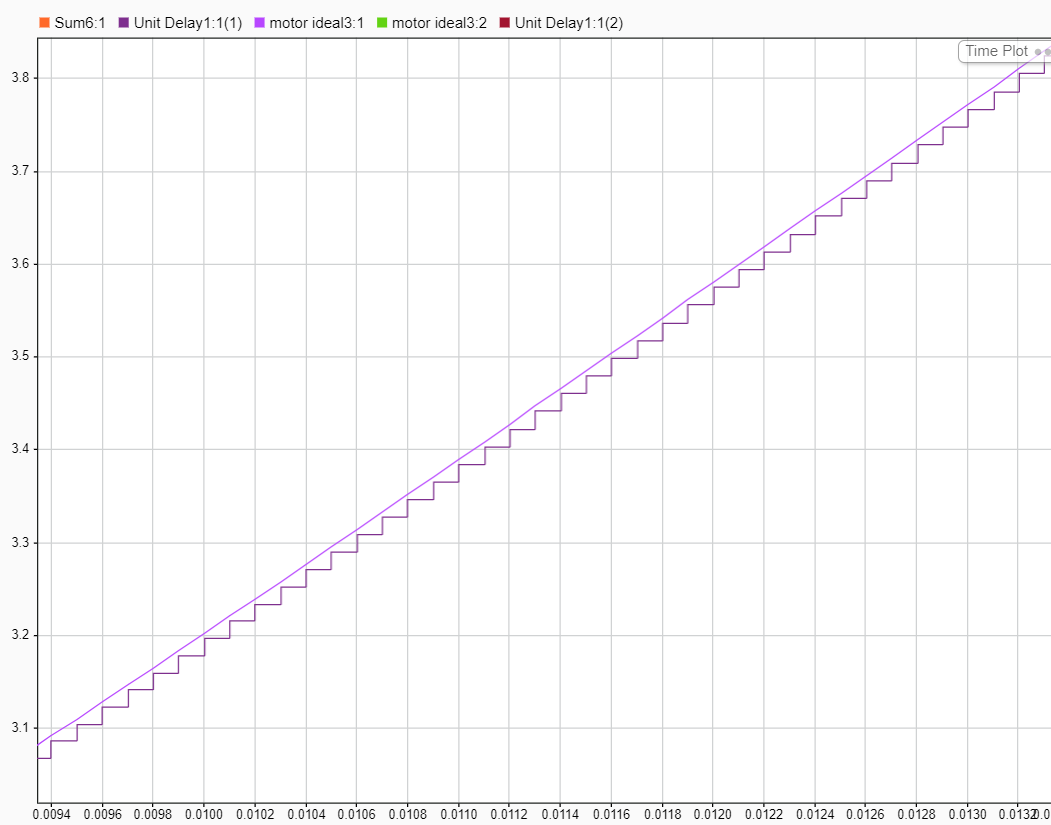

Probamos a bajar los polos para ver cómo afectan e introducimos en el bloque de control del motor el ejemplo real hecho en el apartado 3

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';


T=0.0001    %periodo de muestreo

T = 1.0000e-04

sys=ss(A,B,C,D)

sys =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -61.66
 
  B = 
         u1
   x1     0
   x2  6240
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties

sysd=c2d(sys,T)

sysd =
 
  A = 
              x1         x2
   x1          1  9.969e-05
   x2          0     0.9939
 
  B = 
              u1
   x1  3.113e-05
   x2     0.6221
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.0001 seconds
Discrete-time state-space model.


Fz=sysd.A

Fz =     1.0000    0.0001
         0    0.9939


Gz=sysd.B

Gz =     0.0000
    0.6221


P=[-61.66*1.2/2;-61.66*1.2/2]; %polos de L
Pexp=exp(P*T)

Pexp =     0.9963
    0.9963


Lz=acker(Fz,Gz,Pexp)'

Lz =     0.2192
    0.0020


P=[-61.66*0.5/2;-61.66*0.5/2]; %polos de K y ki
Pexp=exp(P*T)

Pexp =     0.9985
    0.9985


K=acker(Fz,Gz,Pexp)

K =     0.0381   -0.0049


Las ampliadas:

Famp=[Fz,[0;0];T*C,1]

Famp =     1.0000    0.0001         0
         0    0.9939         0
    0.0001         0    1.0000


Gamp=[Gz;0]

Gamp =     0.0000
    0.6221
         0


Cz=C

Cz = 1×2
     1     0


Dz=D

Dz = 0

P=[-61.66*0.5/2;-61.66*0.5/2;-61.66*1.5/2]; %polos de K y ki
Pexp=exp(P*T)

Pexp = 3×1
    0.9985
    0.9985
    0.9954


Kamp=acker(Famp,Gamp,Pexp)

Kamp = 1×3
    0.2665    0.0025    1.7598


Kiz=[Kamp(3)]

Kiz = 1.7598

Kz=[Kamp(1),Kamp(2)]

Kz = 1×2
    0.2665    0.0025


El problema es que la posición queda entre un valor arriba y abajo de la posición que queremos controlar y la velocidad por lo tanto se dispara.

La salida de la posicion del motor y la estimada:

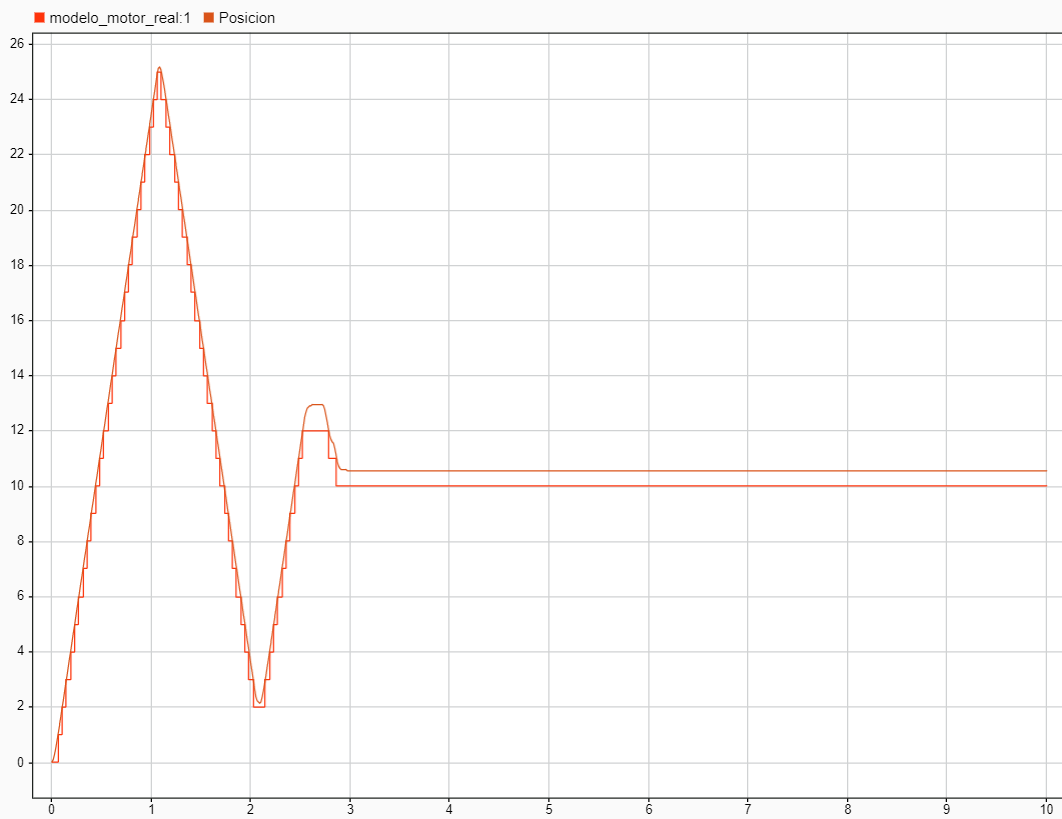

La velocidad del motor y estimada:

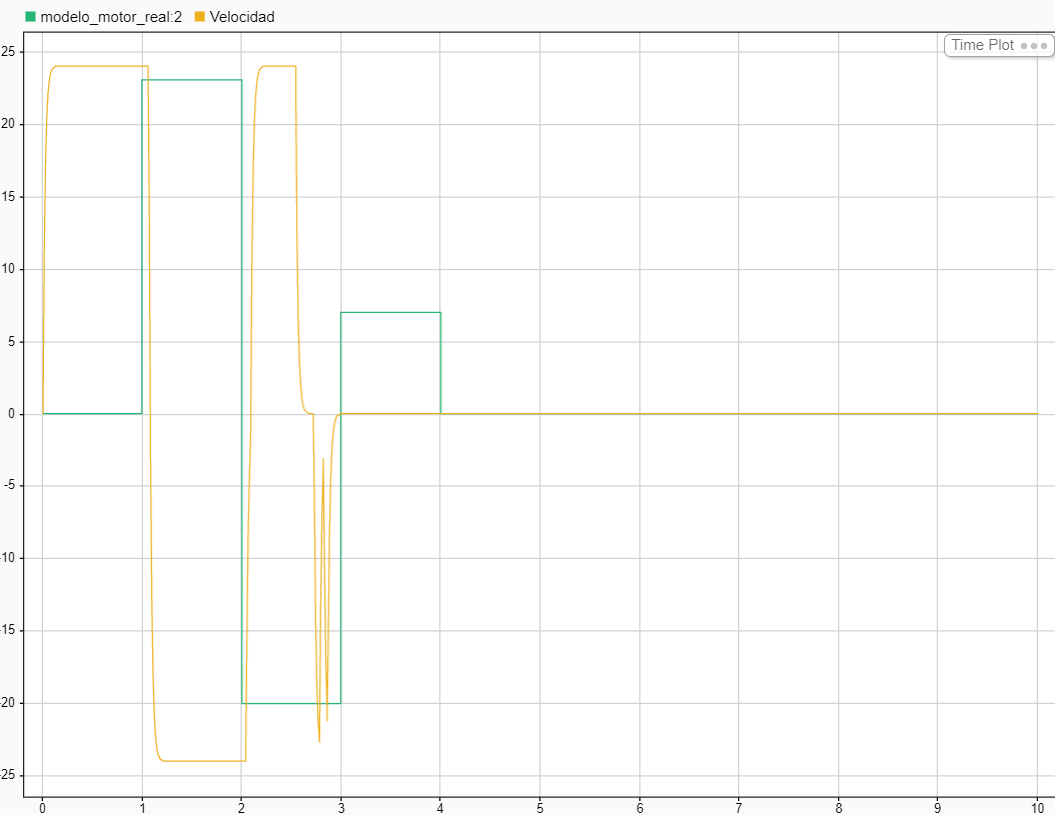

Vemos que se consigue un control a la posición deseada de 10 (la cuál se cambió respecto a la imagen de simulink anterior)

## **Preguntas Práctica 5:**

**1. Diseñar un sistema de control basado en realimentación de estados para el motor, empleando los parámetros Ke y p identificados en la práctica 2.**

    Es el que se ha mostrado en las anteriores líneas 

**2. Estudiar el efecto de la posicion de los polos y los valores de f en la respuesta obtenida para entradas escalón. Examinar el efecto sobre la entrada del sistema u**

La entrada u del sistema con los polos empleados hasta ahora:

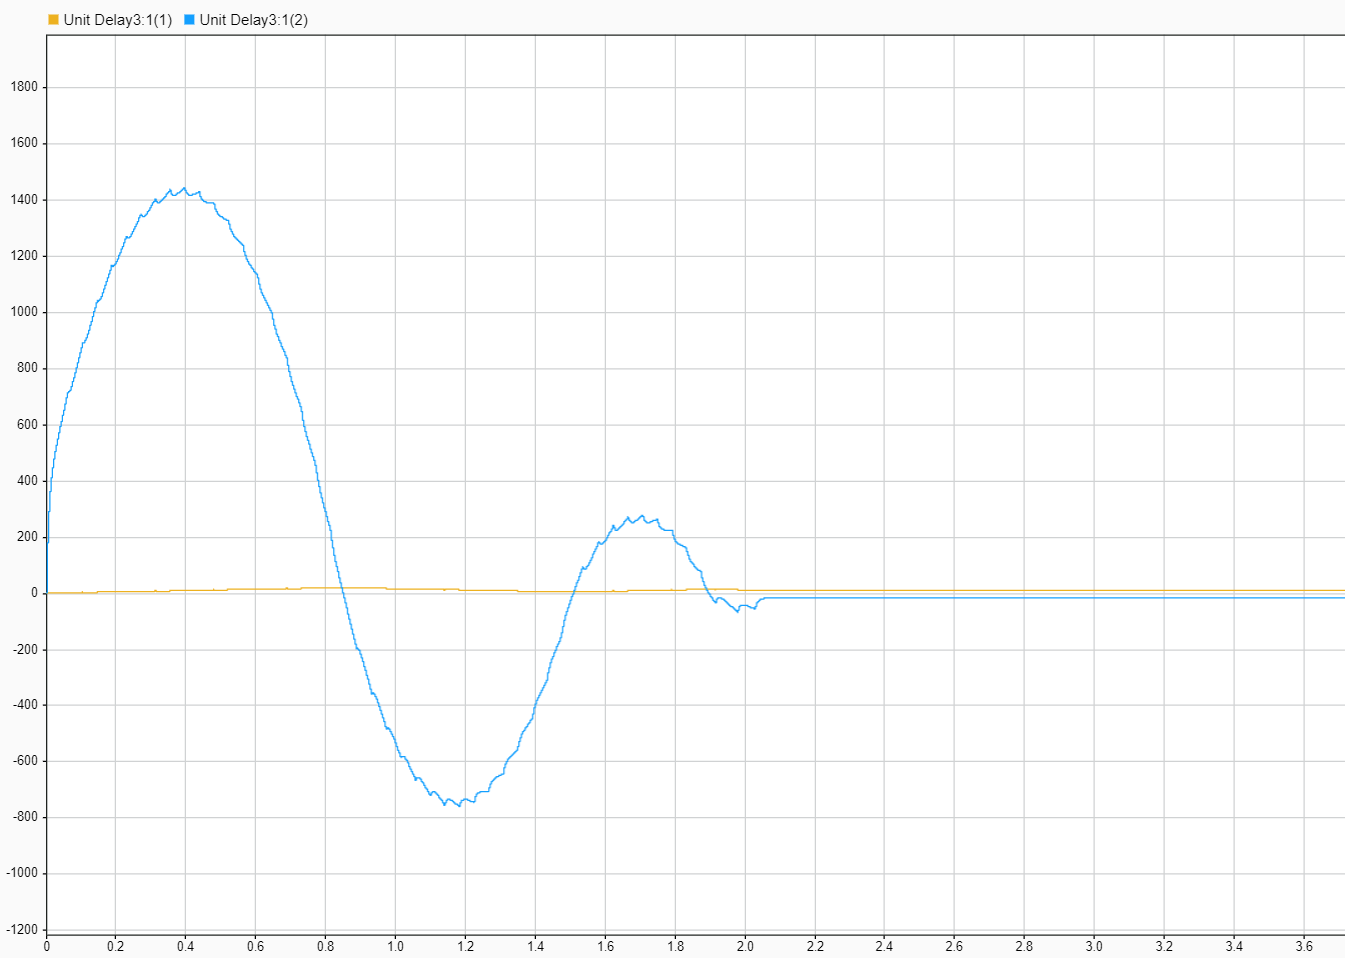

**Más negativos**

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*2;-61.66*2];
L=acker(A,B,P)';


T=0.0001;    %periodo de muestreo
sys=ss(A,B,C,D);
sysd=c2d(sys,T);

Fz=sysd.A;
Gz=sysd.B;
P=[-61.66*1.2;-61.66*1.2]; %polos de L
Pexp=exp(P*T);
Lz=acker(Fz,Gz,Pexp)';
P=[-61.66*1.5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T);
K=acker(Fz,Gz,Pexp);


Las ampliadas:

Famp=[Fz,[0;0];T*C,1];
Gamp=[Gz;0];
Cz=C;
Dz=D;
P=[-61.66*1.5;-61.66*1.5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T);
Kamp=acker(Famp,Gamp,Pexp);
Kiz=[Kamp(3)];
Kz=[Kamp(1),Kamp(2)];

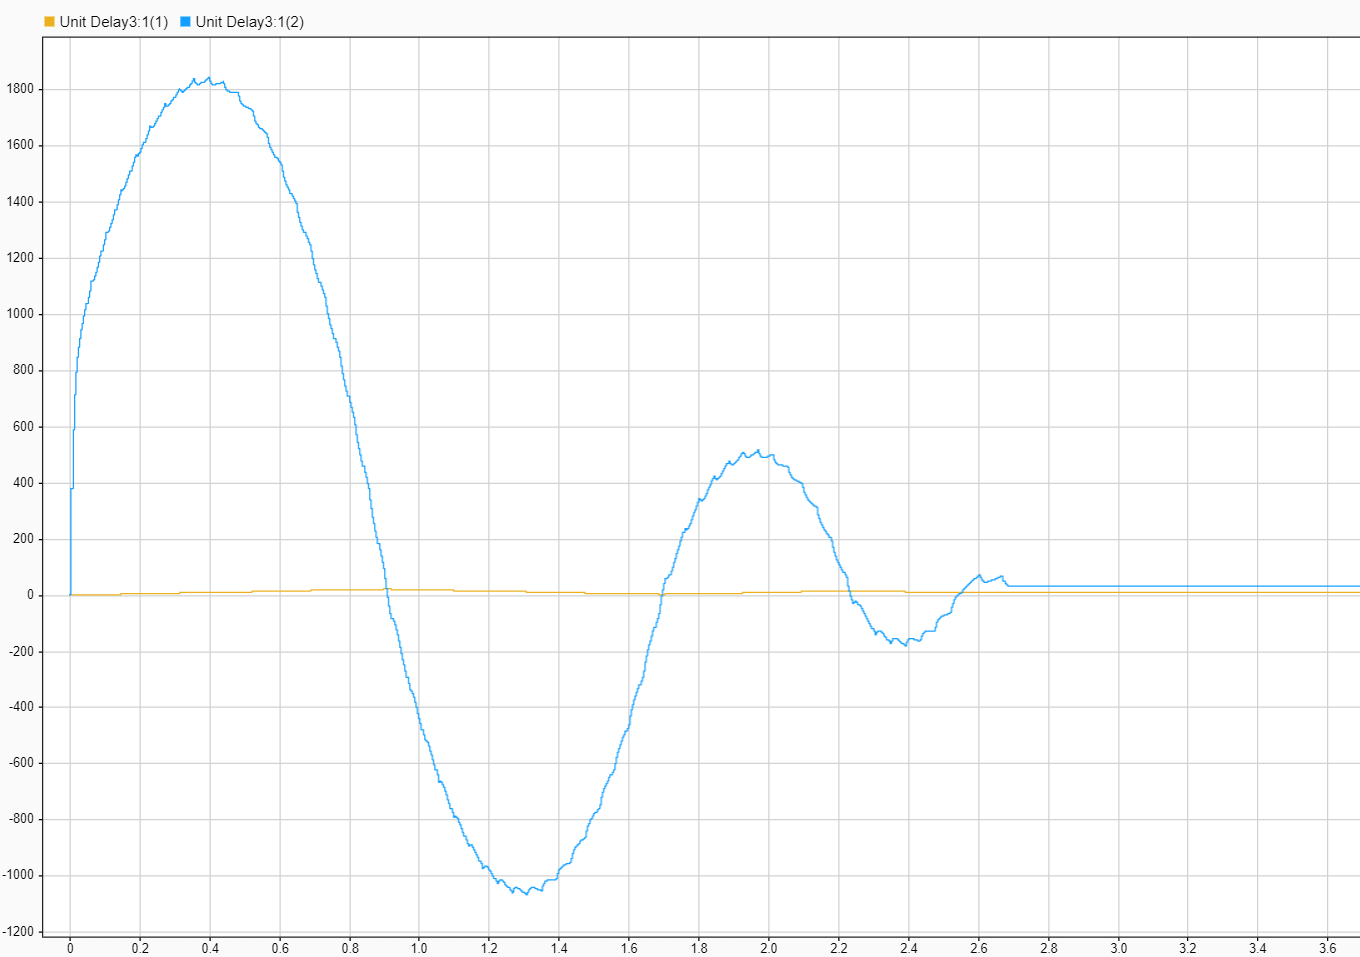

Vemos que la señal de control aumenta así como el tiempo de convergencia

**Menos negativos** (más a la derecha)

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.2;-61.66*1.2];
L=acker(A,B,P)';


T=0.0001;    %periodo de muestreo
sys=ss(A,B,C,D);
sysd=c2d(sys,T);

Fz=sysd.A;
Gz=sysd.B;
P=[-61.66*1.2/4;-61.66*1.2/4]; %polos de L
Pexp=exp(P*T);
Lz=acker(Fz,Gz,Pexp)';
P=[-61.66*0.5/4;-61.66*0.5/4]; %polos de K y ki
Pexp=exp(P*T);
K=acker(Fz,Gz,Pexp);


Las ampliadas:

Famp=[Fz,[0;0];T*C,1];
Gamp=[Gz;0];
Cz=C;
Dz=D;
P=[-61.66*0.5/4;-61.66*0.5/4;-61.66*1.5/2]; %polos de K y ki
Pexp=exp(P*T);
Kamp=acker(Famp,Gamp,Pexp);
Kiz=[Kamp(3)];
Kz=[Kamp(1),Kamp(2)];

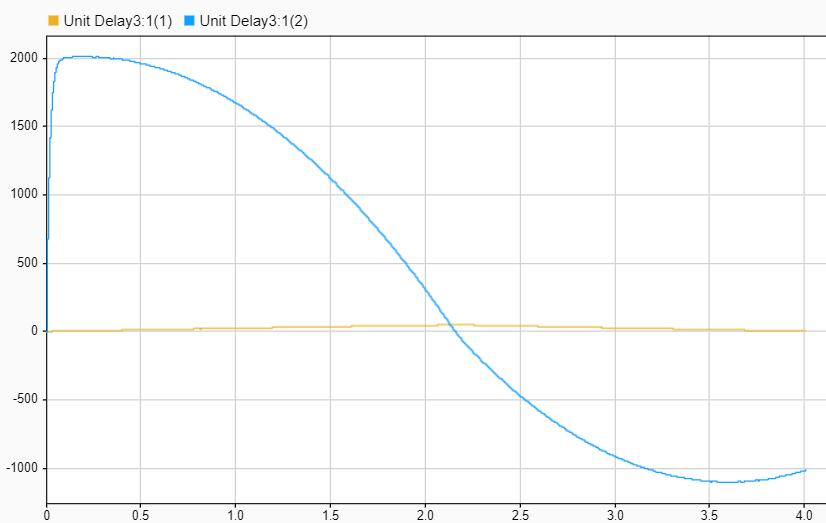

Vemos que el tiempo de convergencia se nos hace muy grande. La amplitud de la entrada aumenta también .

Un caso de interés es el siguiente:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.2;-61.66*1.2];
L=acker(A,B,P)';


T=0.0001    %periodo de muestreo

T = 1.0000e-04

sys=ss(A,B,C,D);
sysd=c2d(sys,T);

Fz=sysd.A;
Gz=sysd.B;
P=[-61.66*1.2;-61.66*1.2]; %polos de L
Pexp=exp(P*T);
Lz=acker(Fz,Gz,Pexp)';
P=[-61.66*0.5;-61.66*0.5]; %polos de K y ki
Pexp=exp(P*T);
K=acker(Fz,Gz,Pexp);


Las ampliadas:

Famp=[Fz,[0;0];T*C,1];
Gamp=[Gz;0];
Cz=C;
Dz=D;
P=[-61.66*0.5;-61.66*0.5/5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T);
Kamp=acker(Famp,Gamp,Pexp);
Kiz=[Kamp(3)];
Kz=[Kamp(1),Kamp(2)];

Donde todos los polos se alejan más hacia la izd menos uno de los polos de K que se lleva a la derecha:

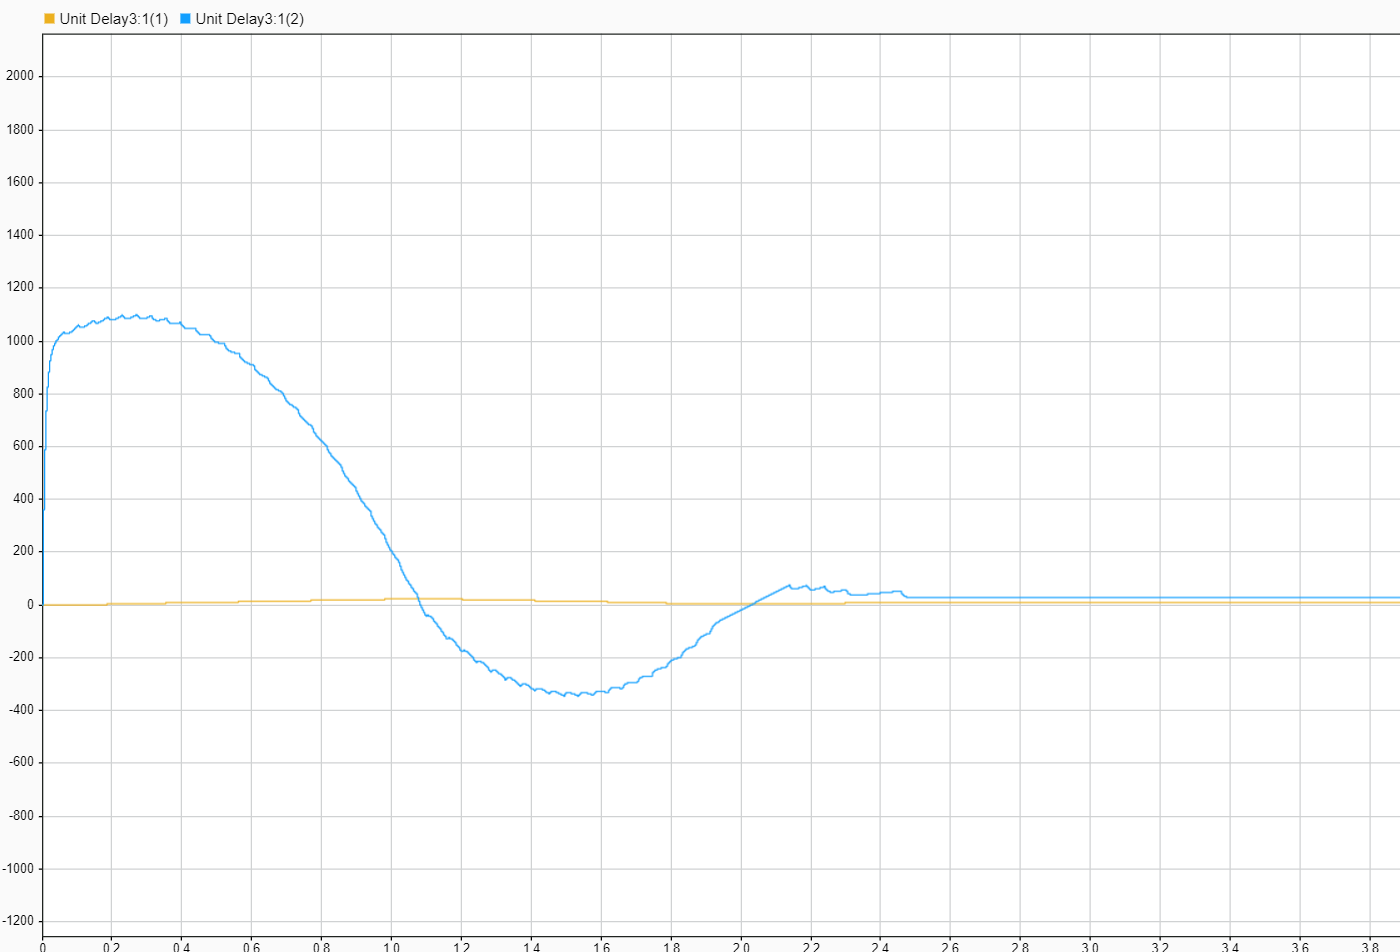

Donde se disminuye el valor de la señal de entrada.

Para las condiciones iniciales de los polos ahora el cambio de la ganancia de la acción integral va a afectar de la siguiente manera:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';


T=0.0001    %periodo de muestreo

T = 1.0000e-04

sys=ss(A,B,C,D);
sysd=c2d(sys,T);
Fz=sysd.A;
Gz=sysd.B;
P=[-61.66*1.2;-61.66*1.2]; %polos de L
Pexp=exp(P*T);
Lz=acker(Fz,Gz,Pexp)';
P=[-61.66*0.5;-61.66*0.5]; %polos de K y ki
Pexp=exp(P*T);
K=acker(Fz,Gz,Pexp);


Las ampliadas:

Famp=[Fz,[0;0];T*C,1];
Gamp=[Gz;0];
Cz=C;
Dz=D;
P=[-61.66*0.5;-61.66*0.5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T);
Kamp=acker(Famp,Gamp,Pexp);
Kiz=[Kamp(3)];
Kz=[Kamp(1),Kamp(2)];

Para el valor de ganancia de entrada **f=1**

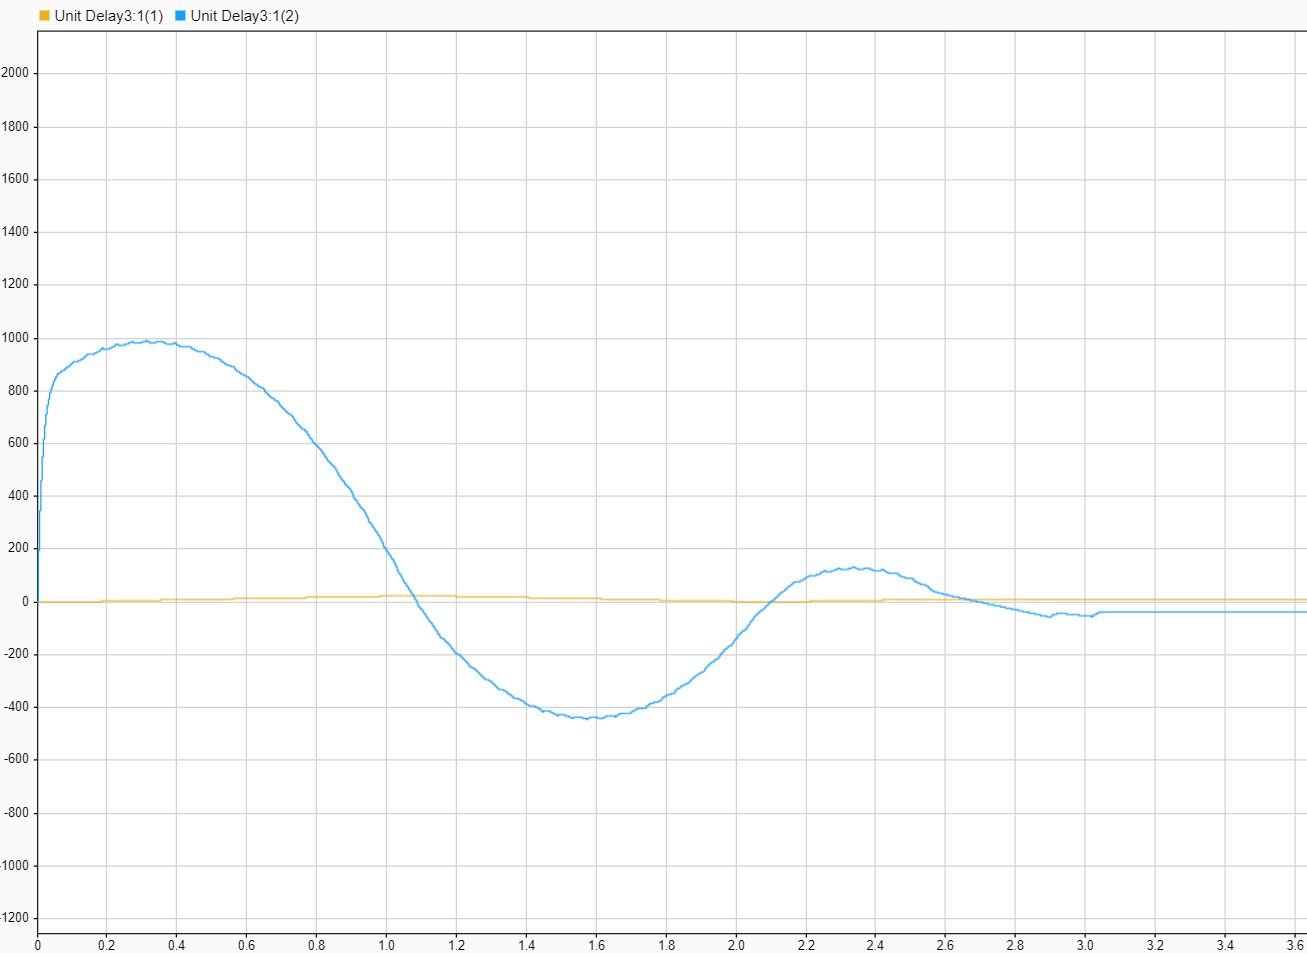

y para **f=0.5:**

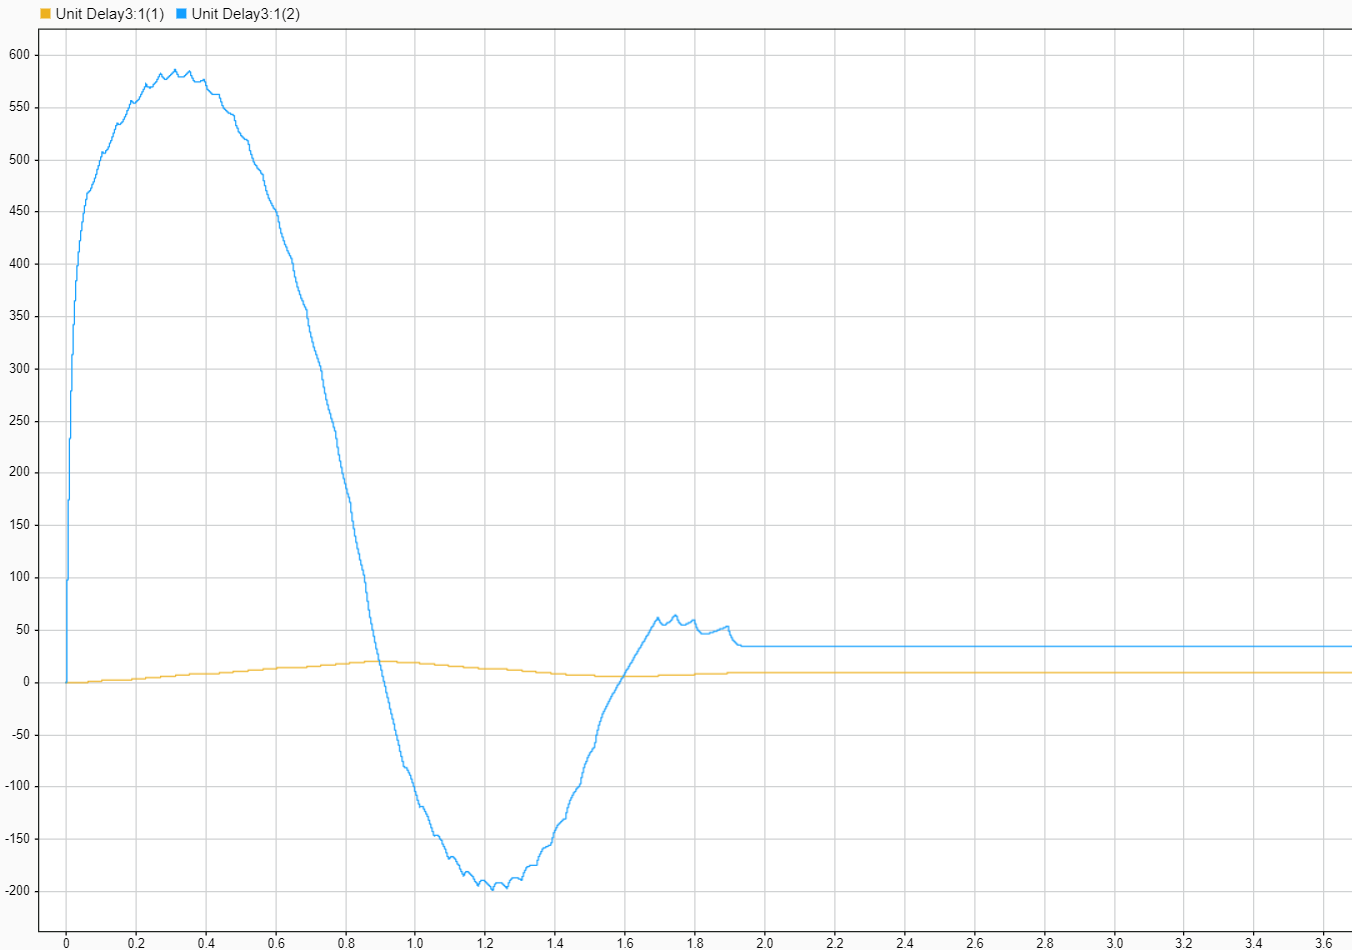

Vemos que se reduce tanto la señal de entrada como el tiempo de convergencia.

La ganancia f va a permitirnos entonces una forma de controlar la amplitud de la señal entrada para ajustarla sin tener que cambiar los polos a través deajustar la acción directa.

**Comentarios:**

Debido al efecto de la acción integral en el error se nos presentan las oscilaciones que vemos en los casos anteriores. Se produce porque el efecto de la acción integral en el error es más rápido que la capacidad de movimiento del motor con sus 12 voltios. Lo que ocurre es que ese error se va acumulando hasta que el motor llega a la posición de consigna pero la acción integral es la que empuja ahora el motor hasta volver a reducir el error. Esto produce un efecto oscilante como el observado, por ello el factor f más pequeño reduce estas oscilaciones.

En la siguiente sección crearemos un bloque que permitirá modular el efecto de la acción integral para reducir este efecto. Recibe el nombre de anti wind-up.

# 4.3. Controlador discreto para el modelo completo del motor y el motor real 

## Preguntas práctica 6

**1. Construir los bloques de Simulink del estimador acción directa y acción integral discreta y añadirlos al modelo de motor completo desarrollado en la práctica 3. **

Introduciremos el modelo de motor de la practica 3:

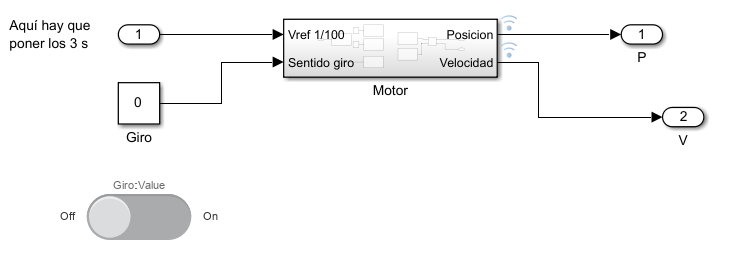

En el bloque de motor de nuestro sistema de control y añadiremos el bloque anti wind-up quedando:

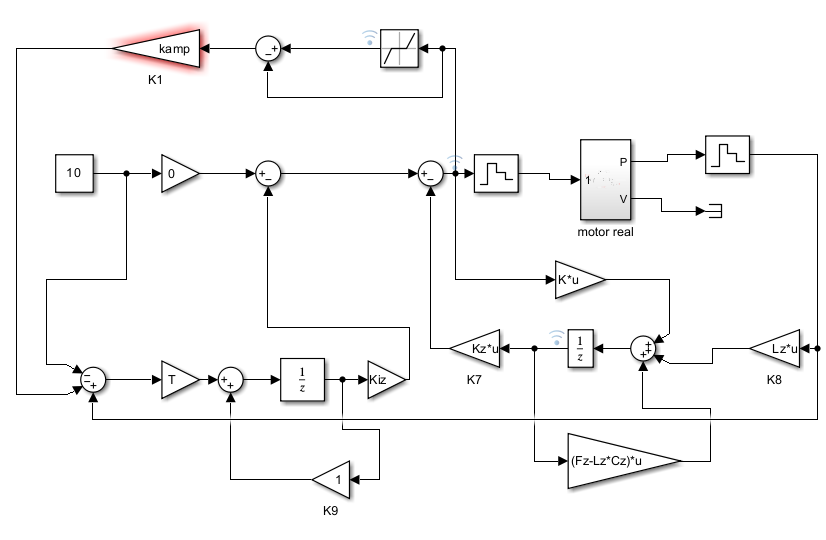

Para que la señal de entrada pueda manejar el controlador del motor hace falta distinguir el signo de la señal como dirección de giro y meter el módulo como señal de entrada del motor de la siguiente manera:

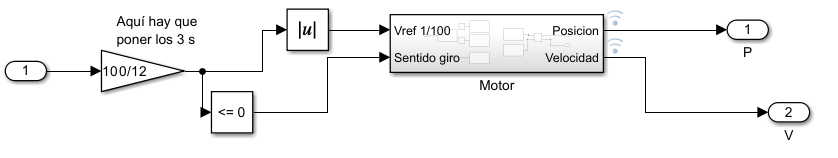

Condiciones de control:

A=[0,1;0,-61.66];
K=gan;
C=[1 0];
B=[0;6239.7];
D=0;
P=[-61.66*1.5;-61.66*1.5];
L=acker(A,B,P)';


T=0.0001;    %periodo de muestreo
sys=ss(A,B,C,D);
sysd=c2d(sys,T);
Fz=sysd.A;
Gz=sysd.B;
P=[-61.66*1.2;-61.66*1.2]; %polos de L
Pexp=exp(P*T);
Lz=acker(Fz,Gz,Pexp)';
P=[-61.66*0.5;-61.66*0.5]; %polos de K y ki
Pexp=exp(P*T);
K=acker(Fz,Gz,Pexp);


Las ampliadas:

Famp=[Fz,[0;0];T*C,1];
Gamp=[Gz;0];
Cz=C;
Dz=D;
P=[-61.66*0.5;-61.66*0.5;-61.66*1.5]; %polos de K y ki
Pexp=exp(P*T);
Kamp=acker(Famp,Gamp,Pexp);
Kiz=[Kamp(3)];
Kz=[Kamp(1),Kamp(2)];

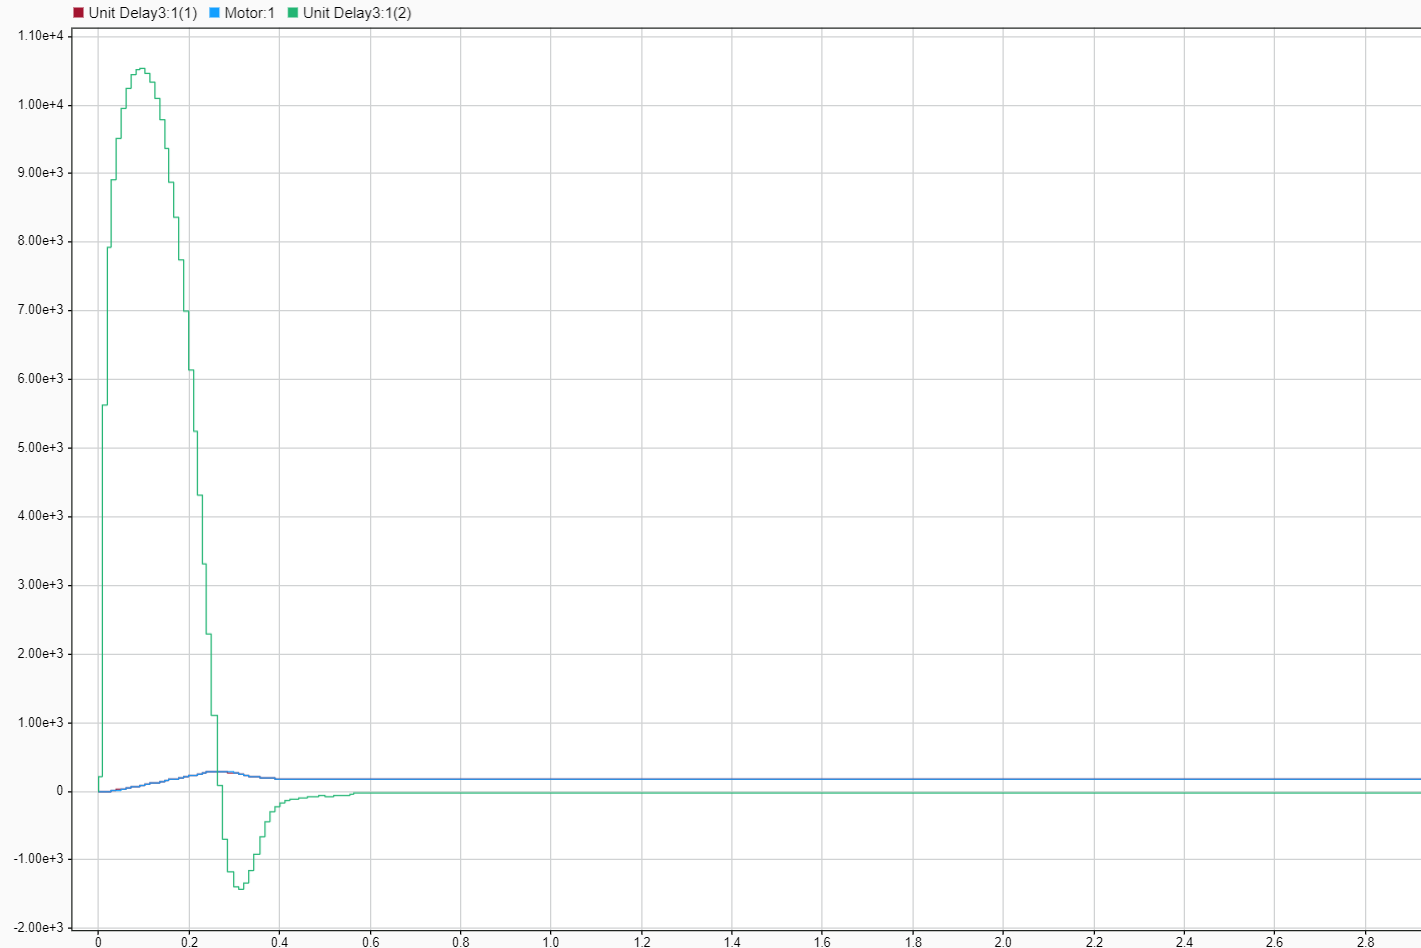

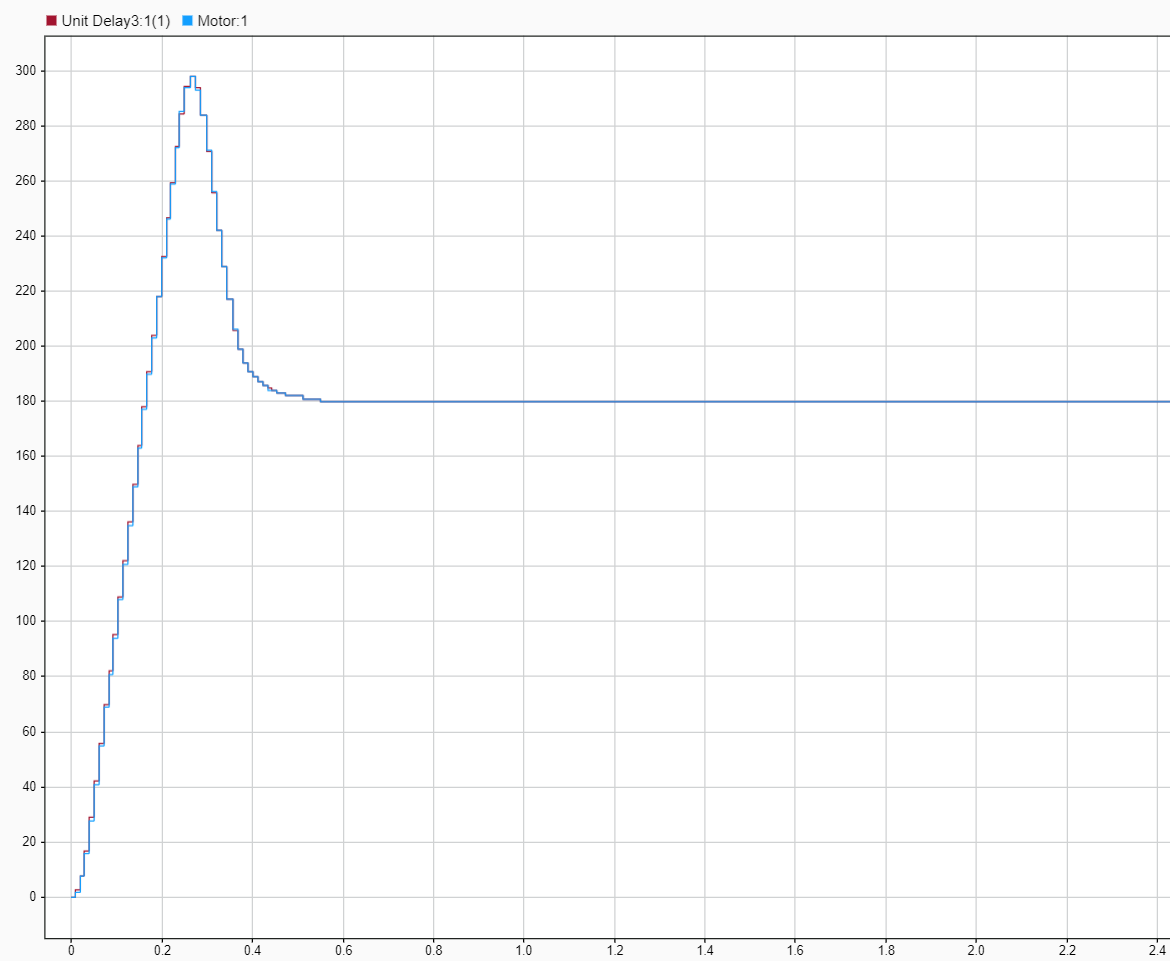

**2. Estudiar la respuesta del sistema para los sistemas de control diseñados en la práctica 5. Comprobar el efecto de eliminar la acción integral Kiz = 0 o la acción directa f = 0 **

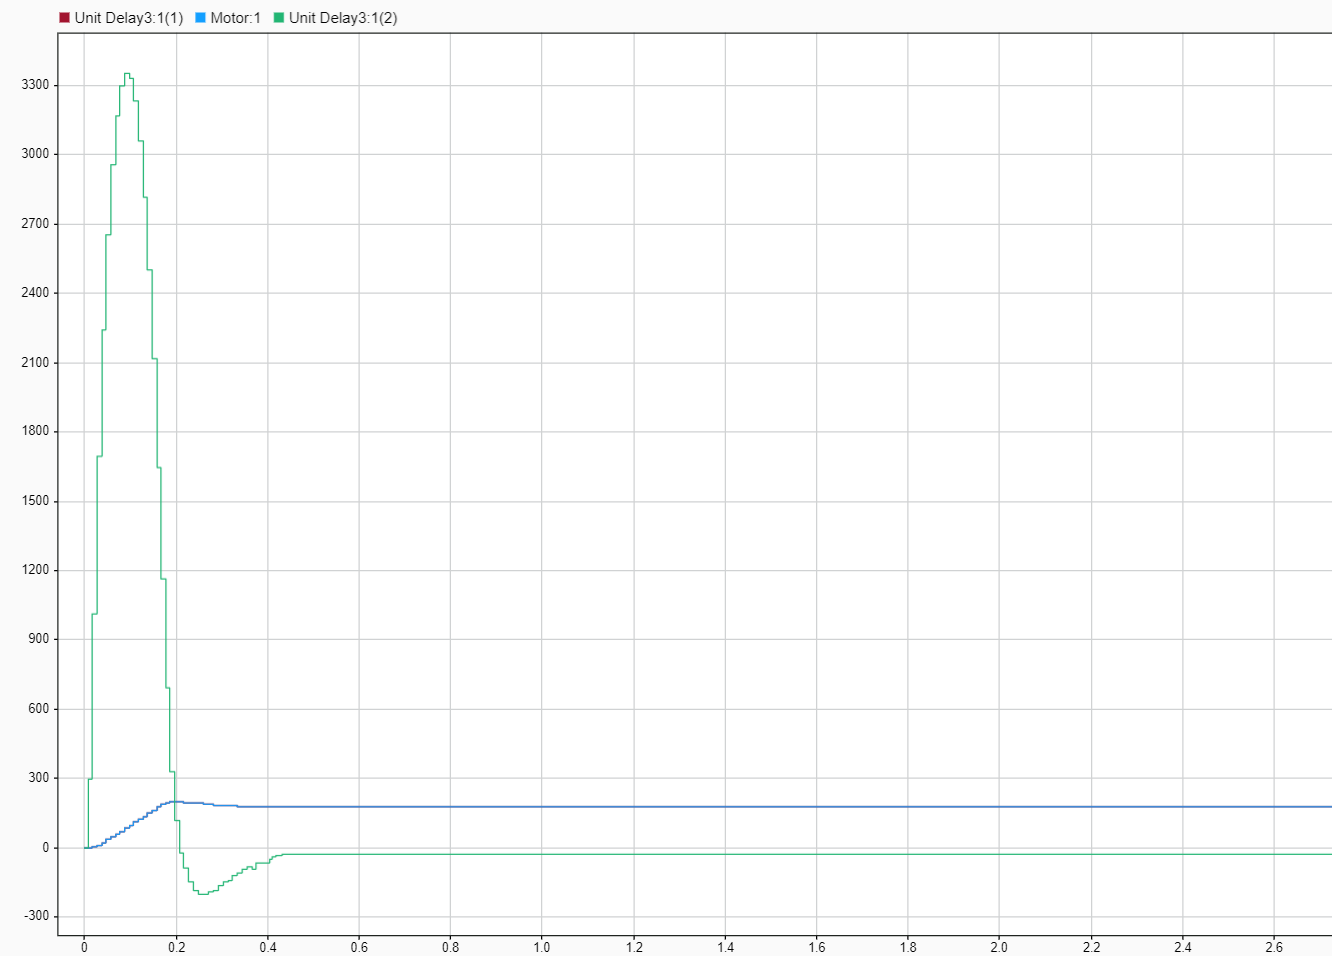

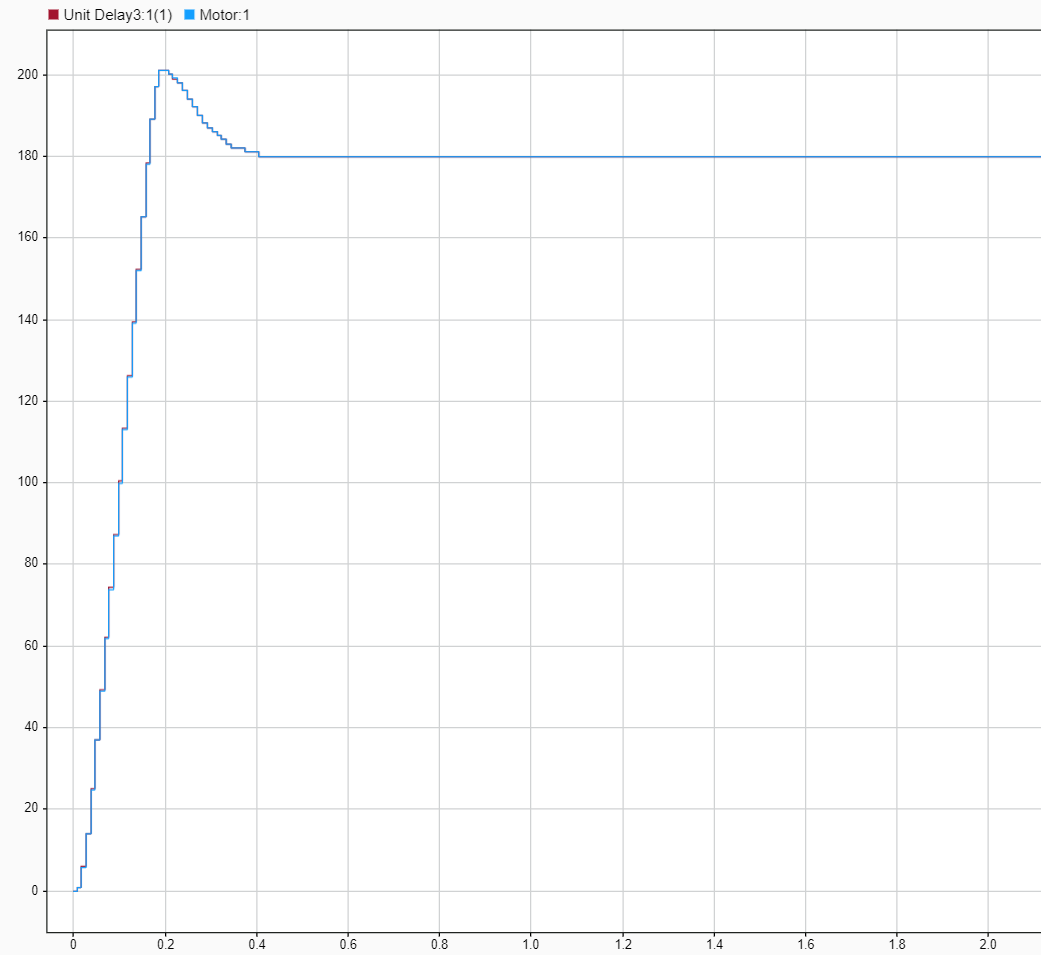

Podemos ver que el control funciona y se alcanza el valor de consigna de 180º siguiendo el motor real al modelo.

Si aumentamos el giro esperamos que la señal de entrada sea mucho mayor para llegar a la posición de consigna, al no poder tomar esos valores el motor limitado a 12V el error de la acción integral se acumula creando el efecto de oscilación que con las mismas condiciones es mucho más notable para valores de consigna altos. Probemos con posición deseada de 800º

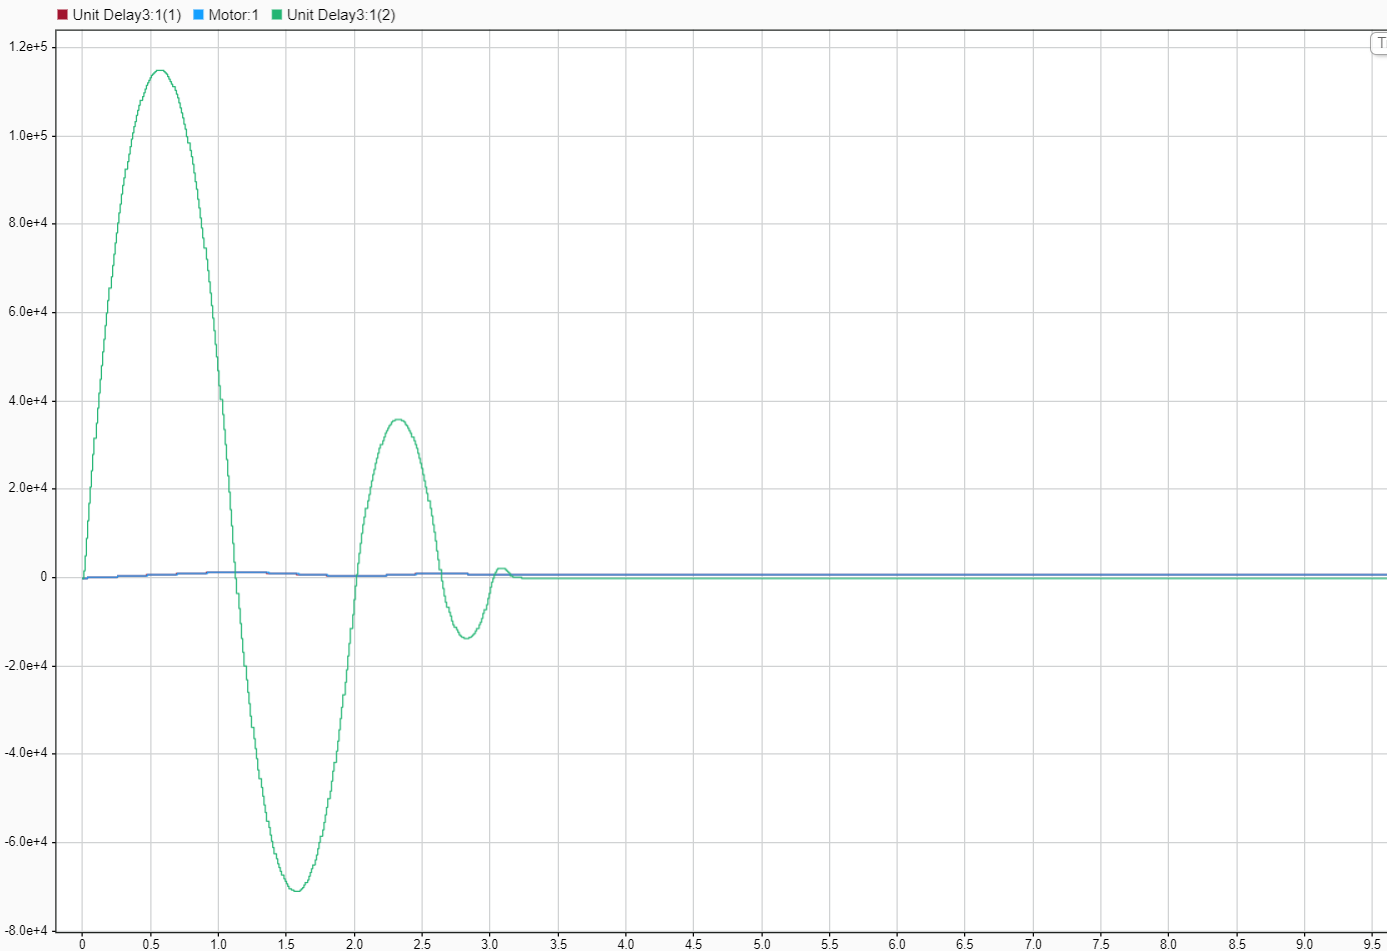

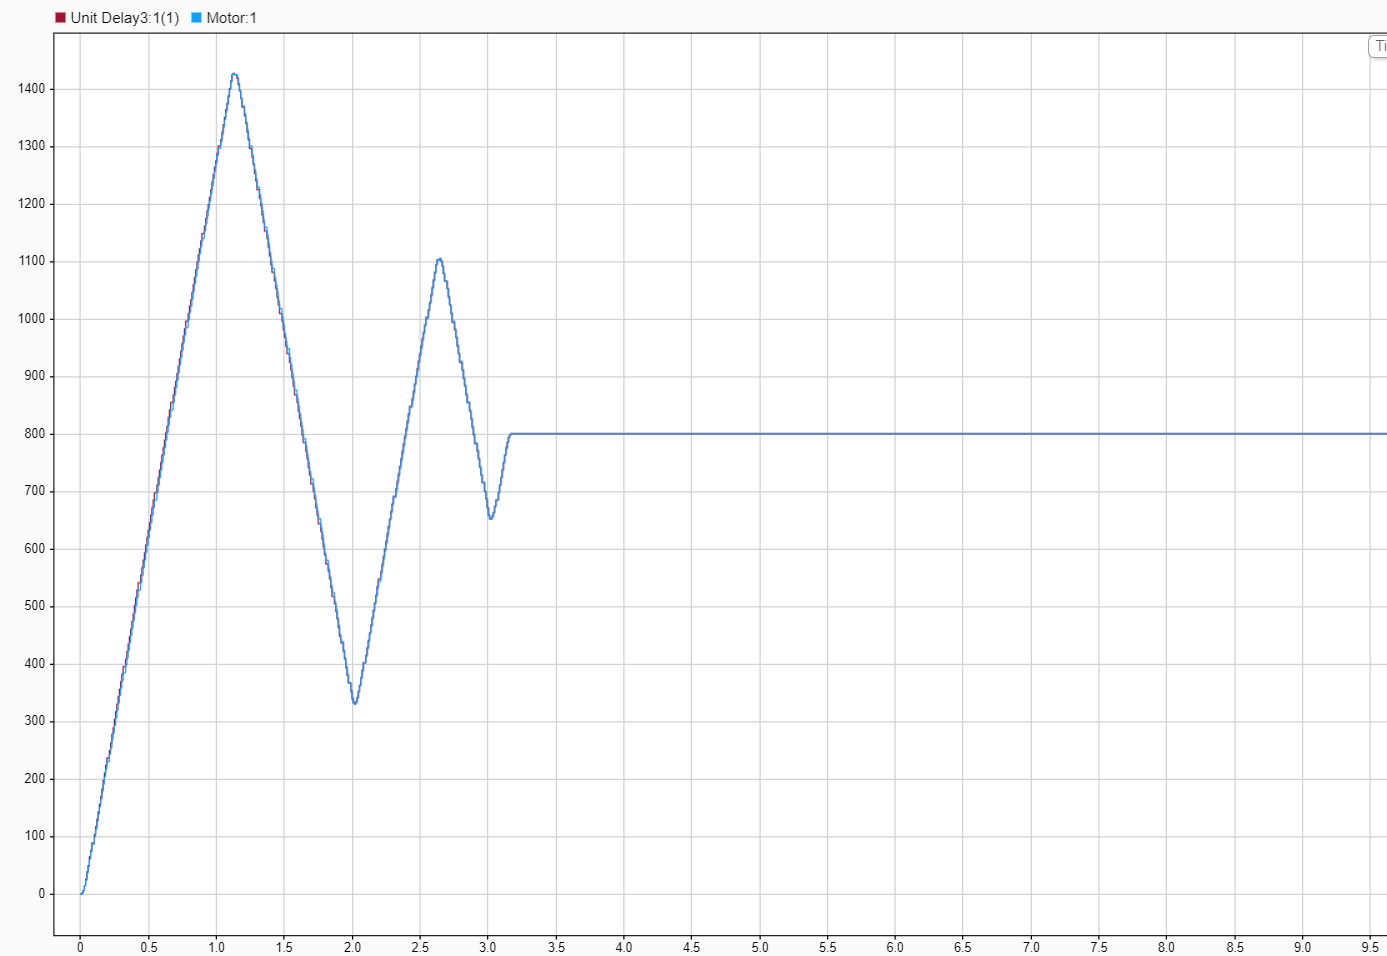

**3. Añadir al modelo un bloque anti wind-up, analizar la salida para distintos valores de la constante kamp.**

Probemos entonces a meter un valor de anti wind up de 10:

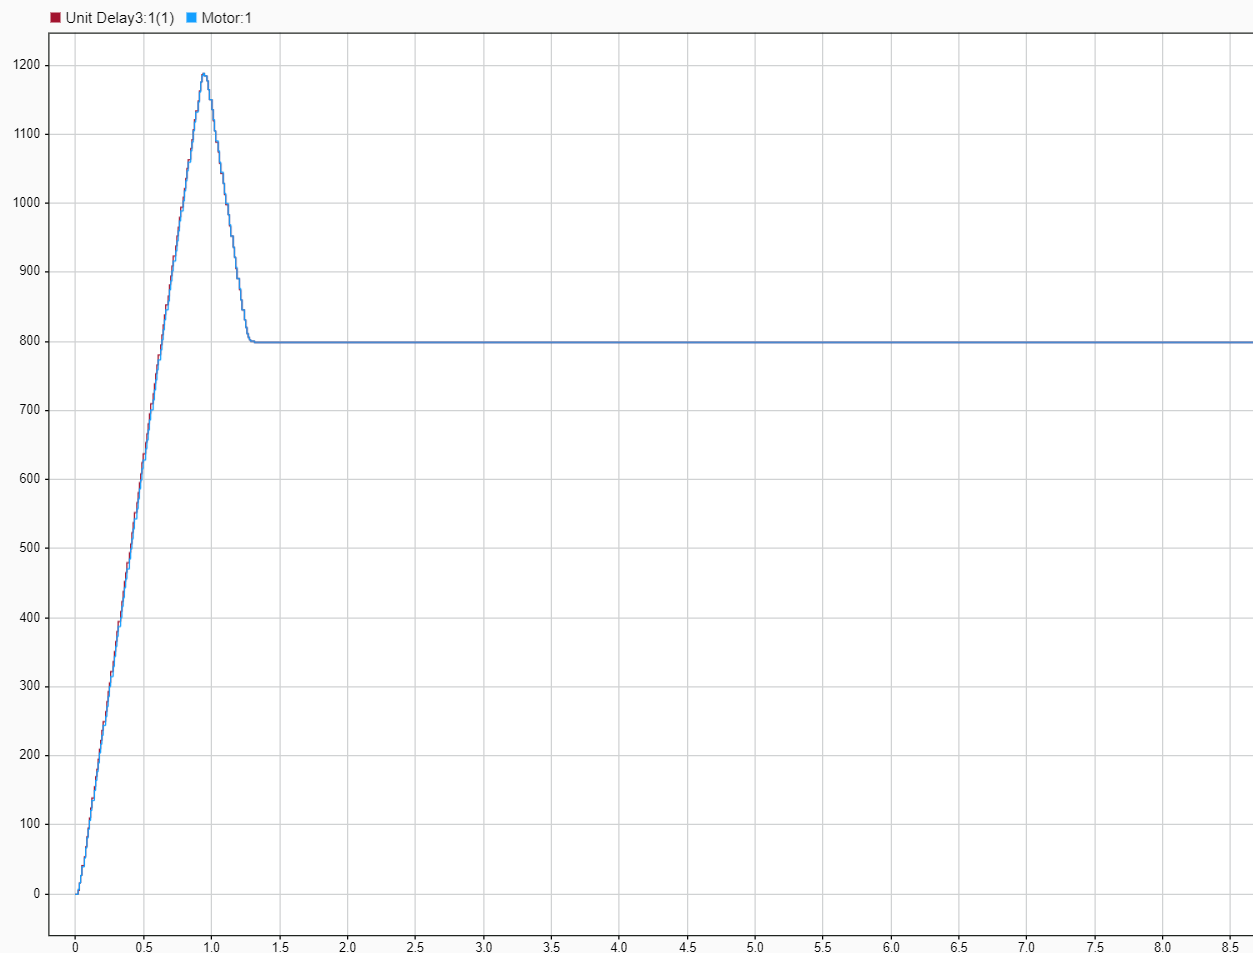

Vemos que el anti wind up realiza su función y limita la acumulación de error del sistema produciéndose una oscilación mucho menor así como una convergencia mucho más rápida.

Si se sobrelimita con una Kamp de 100 podemos no llegar a alcanzar nuestro valor de consigna:

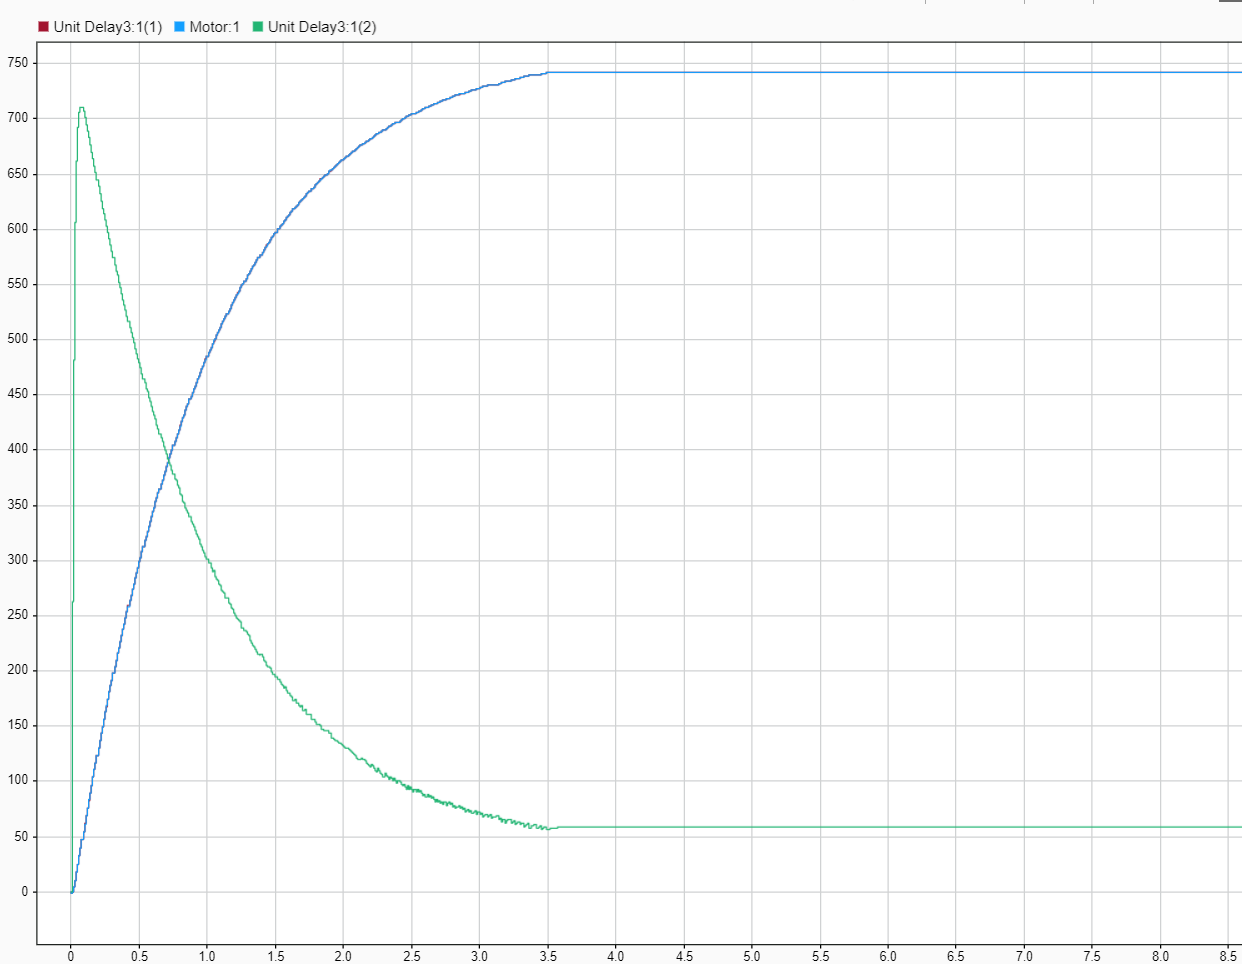

Lo que vemos es que la limitación en nuestra acción integral nos dispara el tiempo de convergencia de forma que este se hace infinito.

Podemos concluir que el sistema de control diseñado para el motor es satisfactorio y permite hacernos una idea práctica de los conceptos de control estudiados durante estas prácticas.